# Toy problems in SE(2)

## Group Actions

Let's start by initializing two arbitrary SE(2) group elements `g `and `h`.

We shall be visualizing their vector and matrix forms (group actions happen when they are in their matrix form).

% Initialize the variables to work with:
syms x y theta u v beta real

% V2M M2V functions:
v2M_SE2 = @(v) [cos(v(3)), -sin(v(3)), v(1);
                sin(v(3)),  cos(v(3)), v(2);
                        0,         0,    1];

M2v_SE2 = @(M) simplify([M(1,3); 
                M(2,3);
                atan(M(2,1)/M(1,1))], 'Steps', 10, ...
                'IgnoreAnalyticConstraints', true);

% Group action functions:
L_h_ofg = @(g,h) simplify(M2v_SE2(v2M_SE2(h)*v2M_SE2(g)), ...
    'Steps', 10, 'IgnoreAnalyticConstraints', true); 
R_h_ofg = @(g,h) simplify(M2v_SE2(v2M_SE2(g)*v2M_SE2(h)), ...
    'Steps', 10, 'IgnoreAnalyticConstraints', true); 

% Group lifted-actiion functions:
T_gL_h = @(g,h) jacobian(L_h_ofg(g,h), g); T_gR_h = @(g,h) jacobian(R_h_ofg(g,h), g);

% Define the vector form of two points in our group 'g', 'h', and 'e':
g_vec = [x;
         y;
         theta]

$$g\_vec = \left(\begin{array}{c} x\\ y\\ \theta \end{array}\right)$$

h_vec = [u;
         v;
         beta]

$$h\_vec = \left(\begin{array}{c} u\\ v\\ \beta \end{array}\right)$$

e_vec = [0;
         0;
         0] % 'e' is the identity and in a more traditional sense the origin for the manifold

e_vec =      0
     0
     0


% Get the matrix forms for these vectors:
g_mat = v2M_SE2(g_vec)

$$g\_mat = \left(\begin{array}{ccc} \cos\left(\theta \right) & -\sin\left(\theta \right) & x\\ \sin\left(\theta \right) & \cos\left(\theta \right) & y\\ 0 & 0 & 1 \end{array}\right)$$

h_mat = v2M_SE2(h_vec)

$$h\_mat = \left(\begin{array}{ccc} \cos\left(\beta \right) & -\sin\left(\beta \right) & u\\ \sin\left(\beta \right) & \cos\left(\beta \right) & v\\ 0 & 0 & 1 \end{array}\right)$$

e_mat = v2M_SE2(e_vec)

e_mat =      1     0     0
     0     1     0
     0     0     1


Let's show how a group action works step-by-step,

eg = simplify(h_mat*g_mat, 'Steps', 10)

$$eg = \left(\begin{array}{ccc} \cos\left(\beta +\theta \right) & -\sin\left(\beta +\theta \right) & u+x\,\cos\left(\beta \right)-y\,\sin\left(\beta \right)\\ \sin\left(\beta +\theta \right) & \cos\left(\beta +\theta \right) & v+y\,\cos\left(\beta \right)+x\,\sin\left(\beta \right)\\ 0 & 0 & 1 \end{array}\right)$$

Now, if we write it in the vector form, we get,

eg = simplify([eg(1,3); 
          eg(2,3);
          atan(eg(2,1)/eg(1,1))], 'Steps', 10, 'IgnoreAnalyticConstraints', true)

$$eg = \left(\begin{array}{c} u+x\,\cos\left(\beta \right)-y\,\sin\left(\beta \right)\\ v+y\,\cos\left(\beta \right)+x\,\sin\left(\beta \right)\\ \beta +\theta \end{array}\right)$$

The angles have obviously added up, and the vector $\left\lbrack x,y\right\rbrack$ is rotated by $\beta$. 

We shall use the previously functions to do the rest of the computation,

% Let's perform some group actions as a sanity check ~ matrix first, then
% vector form
hg_vec = L_h_ofg(g_vec, h_vec)

$$hg\_vec = \left(\begin{array}{c} u+x\,\cos\left(\beta \right)-y\,\sin\left(\beta \right)\\ v+y\,\cos\left(\beta \right)+x\,\sin\left(\beta \right)\\ \beta +\theta \end{array}\right)$$

gh_vec = R_h_ofg(g_vec, h_vec)

$$gh\_vec = \left(\begin{array}{c} x+u\,\cos\left(\theta \right)-v\,\sin\left(\theta \right)\\ y+v\,\cos\left(\theta \right)+u\,\sin\left(\theta \right)\\ \beta +\theta \end{array}\right)$$

## Group Lifted Actions - Mapping tangent spaces

Next, we shall implement the left and right lifted actions that map velocities in 'g' to velocities in 'gh' or 'hg',

% Now, we can try lifted actions:
T_g_to_T_hg = T_gL_h(g_vec, h_vec)

$$T\_g\_to\_T\_hg = \left(\begin{array}{ccc} \cos\left(\beta \right) & -\sin\left(\beta \right) & 0\\ \sin\left(\beta \right) & \cos\left(\beta \right) & 0\\ 0 & 0 & 1 \end{array}\right)$$

T_g_to_T_gh = T_gR_h(g_vec, h_vec)

$$T\_g\_to\_T\_gh = \left(\begin{array}{ccc} 1 & 0 & -v\,\cos\left(\theta \right)-u\,\sin\left(\theta \right)\\ 0 & 1 & u\,\cos\left(\theta \right)-v\,\sin\left(\theta \right)\\ 0 & 0 & 1 \end{array}\right)$$

These results match the equations described in section A.3 of  this paper [https://link.springer.com/article/10.1140/epjst/e2015-50085-y](https://link.springer.com/article/10.1140/epjst/e2015-50085-y) 

With this understanding, we can try to replicate results in section 3.1.2 in the same paper. Some important lifted actions that will help us define local (body frame) velocity, global (rest frame) velocity, and spatial velocity (think what velocity should the global frame have to produce the same body velocity relatively) are needed to conclude this review before moving onto an example.

% Compute the inverse of a group element -- we do this by first converting
% it to the matrix form, then take its inverse, and finally pull it back to
% the vector form.
gInv_mat = simplify(inv(g_mat), 'Steps', 10)

$$gInv\_mat = \left(\begin{array}{ccc} \cos\left(\theta \right) & \sin\left(\theta \right) & -x\,\cos\left(\theta \right)-y\,\sin\left(\theta \right)\\ -\sin\left(\theta \right) & \cos\left(\theta \right) & x\,\sin\left(\theta \right)-y\,\cos\left(\theta \right)\\ 0 & 0 & 1 \end{array}\right)$$

gInv_vec = M2v_SE2(gInv_mat)

$$gInv\_vec = \left(\begin{array}{c} -x\,\cos\left(\theta \right)-y\,\sin\left(\theta \right)\\ x\,\sin\left(\theta \right)-y\,\cos\left(\theta \right)\\ -\theta \end{array}\right)$$

In order to obtain the ***body velocity*** from the global velocity, we need to map from the tangent space at global frame to the tangent space at the body frame of the robot (tangent space is the space where the velocities of group elements are defined -- $\forall g \in G$, $\dot{g} \in T_e G$),


$$\overset{\circ}{\text{g}} = \frac{\partial{e}}{\partial{g}} \dot{g} = \frac{\partial{g^{-1} g}}{\partial{g}} \dot{g} = T_g L_{g^{-1}} \: \dot{g}$$


Since, we already have $g^{-1}$, we can get the corresponding left-lifted action,

TgLgInv = simplify(subs(T_g_to_T_hg, [x, y, theta, u, v, beta],...
    [x, y, theta, gInv_vec(1), gInv_vec(2), gInv_vec(3)]))

$$TgLgInv = \left(\begin{array}{ccc} \cos\left(\theta \right) & \sin\left(\theta \right) & 0\\ -\sin\left(\theta \right) & \cos\left(\theta \right) & 0\\ 0 & 0 & 1 \end{array}\right)$$

Similar to this, we can get the ***spatial velocity***,


$$\overset{\circ}{\text{g}^S} = \frac{\partial{e}}{\partial{g}} \dot{g} = \frac{\partial{g g^{-1}}}{\partial{g}} \dot{g} = T_g R_{g^{-1}} \: \dot{g}$$


TgRgInv = simplify(subs(T_g_to_T_gh, [x, y, theta, u, v, beta], ...
                [x, y, theta, gInv_vec(1), gInv_vec(2), gInv_vec(3)]))

$$TgRgInv = \left(\begin{array}{ccc} 1 & 0 & y\\ 0 & 1 & -x\\ 0 & 0 & 1 \end{array}\right)$$

Wwe compute the global velocity from body velocity as follows,


$$\dot{g} = \frac{\partial{g}}{\partial{e}} \: \overset{\circ}{\text{g}} = \frac{\partial{ge}}{\partial{e}} \: \overset{\circ}{\text{g}} = T_e L_g \: \overset{\circ}{\text{g}}$$


TeLg = simplify(subs(T_g_to_T_hg, [x, y, theta, u, v, beta], ...
                [0, 0, 0, x, y, theta]))

$$TeLg = \left(\begin{array}{ccc} \cos\left(\theta \right) & -\sin\left(\theta \right) & 0\\ \sin\left(\theta \right) & \cos\left(\theta \right) & 0\\ 0 & 0 & 1 \end{array}\right)$$

And finally, we compute the global velocity from spatial velocity,


$$\dot{g} = \frac{\partial{g}}{\partial{e}} \: \overset{\circ}{\text{g}^S} = \frac{\partial{eg}}{\partial{e}} \: \overset{\circ}{\text{g}^S} = T_e R_g \: \overset{\circ}{\text{g}^S}$$


TeRg = simplify(subs(T_g_to_T_gh, [x, y, theta, u, v, beta], ...
                [0, 0, 0, x, y, theta]))

$$TeRg = \left(\begin{array}{ccc} 1 & 0 & -y\\ 0 & 1 & x\\ 0 & 0 & 1 \end{array}\right)$$

As expected, it just rotates the body frame velocity by $\theta \;\ldotp$

## Adjoint inverse maps in the tangent space

The adjoint-inverse mapping encodes the transfer of velocity between frames on a rigid body. It can be split up into two successive transformations,

- cross product

- inverse rotation

The adjoint-inverse of map between tangent spaces $T_{h_1} G$ and $T_{h_i} G$ is $ \overset{\circ}{\text{h}_i} = Ad^{-1}_{g}  \overset{\circ}{\text{h}_1}$, where g is the transformation between the group elements. Using our initial definition of $g = (x, y, \theta)$, the adjoint inverse map $Ad^{-1}_{g}$ is given by,


$$\left\lbrack \begin{array}{ccc}
\cos \;\theta  & \sin \;\theta  & 0\\
-\sin \;\theta  & \cos \;\theta  & 0\\
0 & 0 & 1
\end{array}\right\rbrack \left\lbrack \begin{array}{ccc}
1 & 0 & -y\\
0 & 1 & x\\
0 & 0 & 1
\end{array}\right\rbrack =\left\lbrack \begin{array}{ccc}
\cos \;\theta  & \sin \;\theta  & x\;\sin \;\theta \;-y\;\cos \;\theta \;\\
-\sin \;\theta  & \cos \;\theta  & x\;\cos \;\theta \;+y\;\sin \;\theta \\
0 & 0 & 0
\end{array}\right\rbrack$$


Let's now define this as an inline function to use later,

AdjInvMap = @(k) simplify(...
    subs(TgLgInv, theta, k(3))*subs(TeRg, [x y], [k(1) k(2)])...
    , 'Steps', 10);

## 2-legged system with pins at the foot

Consider an SE(2) system with 2 legs at diametrically opposite ends of a disk centered at the body center, and the right foot is highlighted in the figure below because it is pinned to the ground.

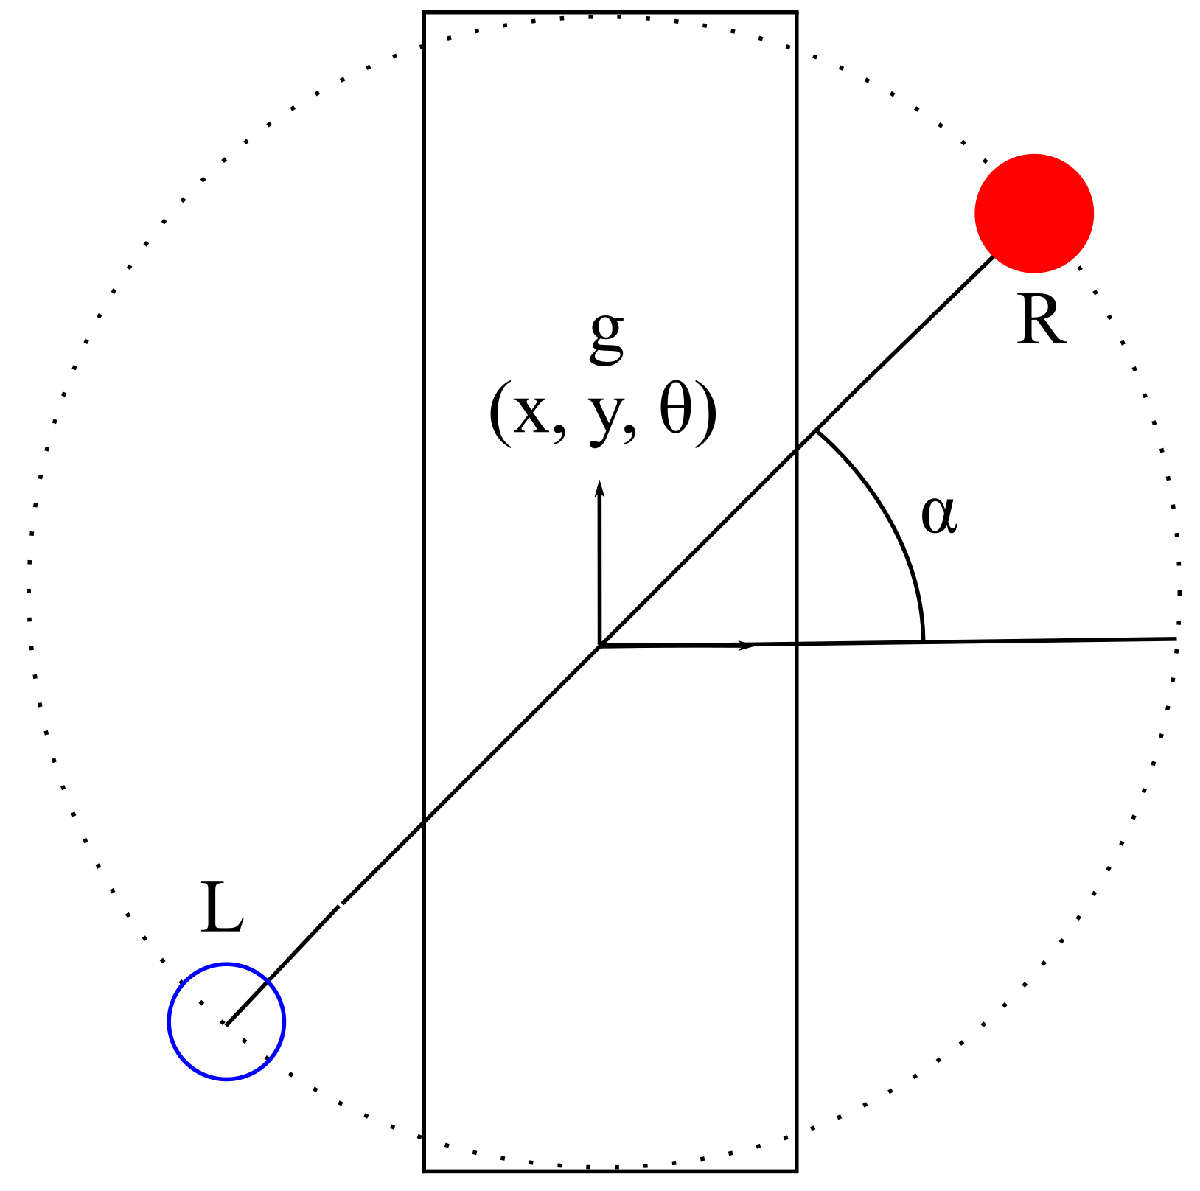

### Transforms and Jacobians

The transforms (denoted by 'h' and the frame name in the subscript) to the feet are pretty straightforward,

syms r alpha alpha_dot real
% Transform to the right leg:
h_R = [r*cos(alpha);
       r*sin(alpha);
       alpha]

$$h\_R = \left(\begin{array}{c} r\,\cos\left(\alpha \right)\\ r\,\sin\left(\alpha \right)\\ \alpha \end{array}\right)$$

% Transform to the left leg:
h_L = [r*cos(pi + alpha);
       r*sin(pi + alpha);
       pi + alpha]

$$h\_L = \left(\begin{array}{c} -r\,\cos\left(\alpha \right)\\ -r\,\sin\left(\alpha \right)\\ \alpha +\pi \end{array}\right)$$

With this, we can now get mappings of the velocities attached to the feet to the center of mass frame ***g*** velocity through the adjoint inverse map,

AdjInv_R = AdjInvMap(h_R)

$$AdjInv\_R = \left(\begin{array}{ccc} \cos\left(\alpha \right) & \sin\left(\alpha \right) & 0\\ -\sin\left(\alpha \right) & \cos\left(\alpha \right) & r\\ 0 & 0 & 1 \end{array}\right)$$

AdjInv_L = AdjInvMap(h_L)

$$AdjInv\_L = \left(\begin{array}{ccc} -\cos\left(\alpha \right) & -\sin\left(\alpha \right) & 0\\ \sin\left(\alpha \right) & -\cos\left(\alpha \right) & r\\ 0 & 0 & 1 \end{array}\right)$$

Now, in order to include the influence of the rotation of the disk $\dot{\;\alpha \;}$, we repeat the third column of the adjoint inverse map we just generated to get the complete foot jacobians as shown below,

footJacobian_R = [AdjInv_R, AdjInv_R(:,end)]

$$footJacobian\_R = \left(\begin{array}{cccc} \cos\left(\alpha \right) & \sin\left(\alpha \right) & 0 & 0\\ -\sin\left(\alpha \right) & \cos\left(\alpha \right) & r & r\\ 0 & 0 & 1 & 1 \end{array}\right)$$

footJacobian_L = [AdjInv_L, AdjInv_L(:,end)]

$$footJacobian\_L = \left(\begin{array}{cccc} -\cos\left(\alpha \right) & -\sin\left(\alpha \right) & 0 & 0\\ \sin\left(\alpha \right) & -\cos\left(\alpha \right) & r & r\\ 0 & 0 & 1 & 1 \end{array}\right)$$

### Connection

Alright, now we can talk about assumptions on the system,

- The anchored foot is not allowed to translate, but can pivot

- The COM frame is allowed to translate, but not rotate

Incorporating this into our right foot jacobian, and swap the column on the LHS with the third column on the RHS to express this as a Pfaffian constraint,


$$\left(\begin{array}{c}
0 \\
0 \\
\overset{\circ}{g^R_{\theta}} \\
\end{array}\right) 

= 

\left(\begin{array}{cccc}
\cos \left(\alpha \right) & \sin \left(\alpha \right) & 0 & 0\\
-\sin \left(\alpha \right) & \cos \left(\alpha \right) & r & r\\
0 & 0 & 1 & 1
\end{array}\right)

\left(\begin{array}{c}
\overset{\circ}{g^1_x} \\
\overset{\circ}{g^1_y} \\
0 \\
\dot{\alpha} \\
\end{array}\right)
 
\Longrightarrow$$
 
$$\left(\begin{array}{c}
0 \\
0 \\
0 \\
\end{array}\right) 

= 

\left(\begin{array}{cccc}
\cos \left(\alpha \right) & \sin \left(\alpha \right) & 0 & 0\\
-\sin \left(\alpha \right) & \cos \left(\alpha \right) & 0 & r\\
0 & 0 & -1 & 1
\end{array}\right)

\left(\begin{array}{c}
\overset{\circ}{g^1_x} \\
\overset{\circ}{g^1_y} \\
\overset{\circ}{g^R_\theta} \\
\dot{\alpha} \\
\end{array}\right) $$


And we shall do the same for the other leg.

omega_R = footJacobian_R; omega_R(:,3) = [0; 0; -1]

$$omega\_R = \left(\begin{array}{cccc} \cos\left(\alpha \right) & \sin\left(\alpha \right) & 0 & 0\\ -\sin\left(\alpha \right) & \cos\left(\alpha \right) & 0 & r\\ 0 & 0 & -1 & 1 \end{array}\right)$$

omega_L = footJacobian_L; omega_L(:,3) = [0; 0; -1]

$$omega\_L = \left(\begin{array}{cccc} -\cos\left(\alpha \right) & -\sin\left(\alpha \right) & 0 & 0\\ \sin\left(\alpha \right) & -\cos\left(\alpha \right) & 0 & r\\ 0 & 0 & -1 & 1 \end{array}\right)$$

Now, we can finally obtain the connection for each foot distinctly,

A_R = -simplify(omega_R(:,1:3)\omega_R(:,4:end))

$$A\_R = \left(\begin{array}{c} r\,\sin\left(\alpha \right)\\ -r\,\cos\left(\alpha \right)\\ 1 \end{array}\right)$$

A_L = -simplify(omega_L(:,1:3)\omega_L(:,4:end))

$$A\_L = \left(\begin{array}{c} -r\,\sin\left(\alpha \right)\\ r\,\cos\left(\alpha \right)\\ 1 \end{array}\right)$$

And there we have our binary switching-mode connections assuming only one leg gets to stay on the ground.

### **Velocity of the unpinned leg**

Let's first assume the ***right leg is pinned to the ground***, and from our connection, we can write out the body velocity as follows,

gcirc__1_r = [1, 0, 0;
            0, 1, 0;
            0, 0, 0]*A_R*alpha_dot % the small r denotes which leg is fixed on the ground

$$gcirc\_\_1\_r = \left(\begin{array}{c} \dot{\alpha }\,r\,\sin\left(\alpha \right)\\ -\dot{\alpha }\,r\,\cos\left(\alpha \right)\\ 0 \end{array}\right)$$

The velocity of the unpinned leg can be obtained by doing another adjoint transformation with respect to *g*  and $\dot{\alpha \;}$,

simplify(footJacobian_L*[gcirc__1_r; alpha_dot])

$$ans = \left(\begin{array}{c} 0\\ 2\,\dot{\alpha }\,r\\ \dot{\alpha } \end{array}\right)$$

Similarly, if the left-leg is anchored and the right-leg drags along, we can obtain a similar expression,

gcirc__1_l = [1, 0, 0;
            0, 1, 0;
            0, 0, 0]*A_L*alpha_dot

$$gcirc\_\_1\_l = \left(\begin{array}{c} -\dot{\alpha }\,r\,\sin\left(\alpha \right)\\ \dot{\alpha }\,r\,\cos\left(\alpha \right)\\ 0 \end{array}\right)$$

gcirc__R_l = simplify(footJacobian_R*[gcirc__1_l; alpha_dot])

$$gcirc\_\_R\_l = \left(\begin{array}{c} 0\\ 2\,\dot{\alpha }\,r\\ \dot{\alpha } \end{array}\right)$$

**The velocities are identical since the frames have the same sense of rotation and are diametrically opposite. Hence, we should have the same power dissipation formulation which will be worked out below **(and we shall just call the dissipation P since it will be the same irrespective of which leg gets to be anchored).

gcirc = gcirc__R_l

$$gcirc = \left(\begin{array}{c} 0\\ 2\,\dot{\alpha }\,r\\ \dot{\alpha } \end{array}\right)$$

Let's start by defining translational viscous friction acting on the passive leg that gets dragged along,

syms nu positive
viscTrans_friction_Mat = -nu*[1, 0, 0;
                              0, 1, 0;
                              0, 0, 0]

$$viscTrans\_friction\_Mat = \left(\begin{array}{ccc} -\nu & 0 & 0\\ 0 & -\nu & 0\\ 0 & 0 & 0 \end{array}\right)$$

P = gcirc' * viscTrans_friction_Mat * gcirc

$$P = -4\,{\dot{\alpha }}^{2}\,\nu \,r^{2}$$

Let's say the the drag matrix $D^{\alpha \;}$is the riemannian metric on the joint space, such that pathlengths $s$ are equal to the time required to traverse paths in the shape space at constant unit power dissipation (quoting **DOI:** [10.1109/TRO.2019.2915424](https://doi.org/10.1109/TRO.2019.2915424)).


$$s = \int \sqrt{d\alpha^T D^\alpha d\alpha}$$


After summing the power lost in all links and interacting frames, the power loss expression assumes a weighted inner-product form with $\dot{\alpha}$,


$$P = \sum_i P_i = \dot{\alpha}^T (\sum_i J_i^{\alpha, T} D_i J_i^\alpha) \dot{\alpha}$$


where, the summation in the middle is the the drag matrix $D^{\alpha \;}$.

D_alpha = P/(alpha_dot^2)

$$D\_alpha = -4\,\nu \,r^{2}$$

## The general case: connection and dissipation metric for the different leg angles

There are a few issues when it comes to computing the connection if in the general case we consider the legs to be independently controlled -- $\alpha_1$ and $\alpha_2$. Unlike the serial link case, each leg-angle only controls the corresponding leg-link and hence, the full jacobian is expected to have a column for zeros for every other joint.

syms r_1 r_2 alpha_1 alpha_2 alpha_dot_1 alpha_dot_2 real
h_R = [r_1*cos(alpha_1);
       r_1*sin(alpha_1);
       alpha_1]

$$h\_R = \left(\begin{array}{c} r_{1}\,\cos\left(\alpha_{1}\right)\\ r_{1}\,\sin\left(\alpha_{1}\right)\\ \alpha_{1} \end{array}\right)$$

h_L = [r_2*cos(alpha_2);
       r_2*sin(alpha_2);
       alpha_2]

$$h\_L = \left(\begin{array}{c} r_{2}\,\cos\left(\alpha_{2}\right)\\ r_{2}\,\sin\left(\alpha_{2}\right)\\ \alpha_{2} \end{array}\right)$$

AdjInv_R = AdjInvMap(h_R)

$$AdjInv\_R = \left(\begin{array}{ccc} \cos\left(\alpha_{1}\right) & \sin\left(\alpha_{1}\right) & 0\\ -\sin\left(\alpha_{1}\right) & \cos\left(\alpha_{1}\right) & r_{1}\\ 0 & 0 & 1 \end{array}\right)$$

AdjInv_L = AdjInvMap(h_L)

$$AdjInv\_L = \left(\begin{array}{ccc} \cos\left(\alpha_{2}\right) & \sin\left(\alpha_{2}\right) & 0\\ -\sin\left(\alpha_{2}\right) & \cos\left(\alpha_{2}\right) & r_{2}\\ 0 & 0 & 1 \end{array}\right)$$


footJacobian_R = [AdjInv_R, AdjInv_R*[0,0,1]', AdjInv_R*[0,0,0]']

$$footJacobian\_R = \left(\begin{array}{ccccc} \cos\left(\alpha_{1}\right) & \sin\left(\alpha_{1}\right) & 0 & 0 & 0\\ -\sin\left(\alpha_{1}\right) & \cos\left(\alpha_{1}\right) & r_{1} & r_{1} & 0\\ 0 & 0 & 1 & 1 & 0 \end{array}\right)$$

footJacobian_L = [AdjInv_L, AdjInv_L*[0,0,0]', AdjInv_L*[0,0,1]']

$$footJacobian\_L = \left(\begin{array}{ccccc} \cos\left(\alpha_{2}\right) & \sin\left(\alpha_{2}\right) & 0 & 0 & 0\\ -\sin\left(\alpha_{2}\right) & \cos\left(\alpha_{2}\right) & r_{2} & 0 & r_{2}\\ 0 & 0 & 1 & 0 & 1 \end{array}\right)$$

### Modes 1 & 2: Anchored right and left legs

As mentioned earlier, the column corresponding to the joint of the other leg should be empty. Rederiving the connections and dissipation metric,


$$\left(\begin{array}{c}
0 \\
0 \\
\overset{\circ}{g^R_{\theta}} \\
\end{array}\right) 

= 

\left(\begin{array}{cccc}
\cos \left(\alpha_1 \right) & \sin \left(\alpha_1 \right) & 0 & 0 & 0\\
-\sin \left(\alpha_1 \right) & \cos \left(\alpha_1 \right) & r_1 & r_1 & 0\\
0 & 0 & 1 & 1 & 0
\end{array}\right)

\left(\begin{array}{c}
\overset{\circ}{g^1_x} \\
\overset{\circ}{g^1_y} \\
0 \\
\dot{\alpha}_1 \\
\dot{\alpha}_2
\end{array}\right)
 
\Longrightarrow$$
 
$$\left(\begin{array}{c}
0 \\
0 \\
0 \\
\end{array}\right) 

= 

\left(\begin{array}{cccc}
\cos \left(\alpha_1 \right) & \sin \left(\alpha_1 \right) & 0 & 0 & 0\\
-\sin \left(\alpha_1 \right) & \cos \left(\alpha_1 \right) & 0 & r_1 & 0\\
0 & 0 & -1 & 1 & 0
\end{array}\right)

\left(\begin{array}{c}
\overset{\circ}{g^1_x} \\
\overset{\circ}{g^1_y} \\
\overset{\circ}{g^R_\theta} \\
\dot{\alpha}_1 \\
\dot{\alpha}_2
\end{array}\right) $$


omega_R = footJacobian_R; omega_R(:,3) = [0, 0, -1]'

$$omega\_R = \left(\begin{array}{ccccc} \cos\left(\alpha_{1}\right) & \sin\left(\alpha_{1}\right) & 0 & 0 & 0\\ -\sin\left(\alpha_{1}\right) & \cos\left(\alpha_{1}\right) & 0 & r_{1} & 0\\ 0 & 0 & -1 & 1 & 0 \end{array}\right)$$

omega_L = footJacobian_L; omega_L(:,3) = [0, 0, -1]'

$$omega\_L = \left(\begin{array}{ccccc} \cos\left(\alpha_{2}\right) & \sin\left(\alpha_{2}\right) & 0 & 0 & 0\\ -\sin\left(\alpha_{2}\right) & \cos\left(\alpha_{2}\right) & 0 & 0 & r_{2}\\ 0 & 0 & -1 & 0 & 1 \end{array}\right)$$

A_R = -simplify(omega_R(:,1:3)\omega_R(:,4:end))

$$A\_R = \left(\begin{array}{cc} r_{1}\,\sin\left(\alpha_{1}\right) & 0\\ -r_{1}\,\cos\left(\alpha_{1}\right) & 0\\ 1 & 0 \end{array}\right)$$

A_L = -simplify(omega_L(:,1:3)\omega_L(:,4:end))

$$A\_L = \left(\begin{array}{cc} 0 & r_{2}\,\sin\left(\alpha_{2}\right)\\ 0 & -r_{2}\,\cos\left(\alpha_{2}\right)\\ 0 & 1 \end{array}\right)$$

The new connection is the more general version of the connection we defined earlier based the active on-the-ground leg.

Since, we don't want the map to the rotational velocity of the pinned leg, we zero the third row of the connection maps.

A_R(3,:) = zeros(1,size(A_R,2)); A_L(3,:) = zeros(1,size(A_L,2));

### Dissipation metric in each mode

Velocity of the rigid body and unpinned leg in each case (anchored leg is denoted by a lower case r or l at the end of velocities),

gcirc__1_r = A_R*[alpha_dot_1; alpha_dot_2]

$$gcirc\_\_1\_r = \left(\begin{array}{c} {\dot{\alpha }}_{1}\,r_{1}\,\sin\left(\alpha_{1}\right)\\ -{\dot{\alpha }}_{1}\,r_{1}\,\cos\left(\alpha_{1}\right)\\ 0 \end{array}\right)$$

gcirc__L_r = simplify(footJacobian_L*[gcirc__1_r; alpha_dot_1; alpha_dot_2])

$$gcirc\_\_L\_r = \left(\begin{array}{c} {\dot{\alpha }}_{1}\,r_{1}\,\sin\left(\alpha_{1}-\alpha_{2}\right)\\ {\dot{\alpha }}_{2}\,r_{2}-{\dot{\alpha }}_{1}\,r_{1}\,\cos\left(\alpha_{1}-\alpha_{2}\right)\\ {\dot{\alpha }}_{2} \end{array}\right)$$

gcirc__1_l = A_L*[alpha_dot_1; alpha_dot_2]

$$gcirc\_\_1\_l = \left(\begin{array}{c} {\dot{\alpha }}_{2}\,r_{2}\,\sin\left(\alpha_{2}\right)\\ -{\dot{\alpha }}_{2}\,r_{2}\,\cos\left(\alpha_{2}\right)\\ 0 \end{array}\right)$$

gcirc__R_l = simplify(footJacobian_R*[gcirc__1_l; alpha_dot_1; alpha_dot_2])

$$gcirc\_\_R\_l = \left(\begin{array}{c} -{\dot{\alpha }}_{2}\,r_{2}\,\sin\left(\alpha_{1}-\alpha_{2}\right)\\ {\dot{\alpha }}_{1}\,r_{1}-{\dot{\alpha }}_{2}\,r_{2}\,\cos\left(\alpha_{1}-\alpha_{2}\right)\\ {\dot{\alpha }}_{1} \end{array}\right)$$

P_r = simplify(gcirc__L_r' * viscTrans_friction_Mat * gcirc__L_r, 'Steps', 10)

$$P\_r = -\nu \,\left({{\dot{\alpha }}_{1}}^{2}\,{r_{1}}^{2}-2\,\cos\left(\alpha_{1}-\alpha_{2}\right)\,{\dot{\alpha }}_{1}\,{\dot{\alpha }}_{2}\,r_{1}\,r_{2}+{{\dot{\alpha }}_{2}}^{2}\,{r_{2}}^{2}\right)$$

P_l = simplify(gcirc__R_l' * viscTrans_friction_Mat * gcirc__R_l, 'Steps', 10)

$$P\_l = -\nu \,\left({{\dot{\alpha }}_{1}}^{2}\,{r_{1}}^{2}-2\,\cos\left(\alpha_{1}-\alpha_{2}\right)\,{\dot{\alpha }}_{1}\,{\dot{\alpha }}_{2}\,r_{1}\,r_{2}+{{\dot{\alpha }}_{2}}^{2}\,{r_{2}}^{2}\right)$$

Here comes the tricky part: we need to express this as a weighted inner-norm to collect the $D_\alpha$ matrix, but since we know what it entails, let's define a generic matrix and see what happens to the terms (we shall only expand it for one of the cases),

D_alpha_r = sym('Dr%d%d',[2,2],'real')

$$D\_alpha\_r = \left(\begin{array}{cc} {\mathrm{Dr}}_{11} & {\mathrm{Dr}}_{12}\\ {\mathrm{Dr}}_{21} & {\mathrm{Dr}}_{22} \end{array}\right)$$

D_alpha_l = sym('Dr%d%d',[2,2],'real');
P_r_gen = expand([alpha_dot_1; alpha_dot_2]'*D_alpha_r*[alpha_dot_1; alpha_dot_2])

$$P\_r\_gen = {\mathrm{Dr}}_{11}\,{{\dot{\alpha }}_{1}}^{2}+{\mathrm{Dr}}_{22}\,{{\dot{\alpha }}_{2}}^{2}+{\mathrm{Dr}}_{12}\,{\dot{\alpha }}_{1}\,{\dot{\alpha }}_{2}+{\mathrm{Dr}}_{21}\,{\dot{\alpha }}_{1}\,{\dot{\alpha }}_{2}$$

Let's collect the square terms separately and since we want to make the matrix symmetric, we can make the off-diagonal terms equal as follows,

[coeffs_r, term_r] = coeffs(P_r, [alpha_dot_1 alpha_dot_2], 'All')

$$coeffs\_r = \left(\begin{array}{ccc} 0 & 0 & -\nu \,{r_{1}}^{2}\\ 0 & 2\,\nu \,r_{1}\,r_{2}\,\cos\left(\alpha_{1}-\alpha_{2}\right) & 0\\ -\nu \,{r_{2}}^{2} & 0 & 0 \end{array}\right)$$

$$term\_r = \left(\begin{array}{ccc} {{\dot{\alpha }}_{1}}^{2}\,{{\dot{\alpha }}_{2}}^{2} & {{\dot{\alpha }}_{1}}^{2}\,{\dot{\alpha }}_{2} & {{\dot{\alpha }}_{1}}^{2}\\ {\dot{\alpha }}_{1}\,{{\dot{\alpha }}_{2}}^{2} & {\dot{\alpha }}_{1}\,{\dot{\alpha }}_{2} & {\dot{\alpha }}_{1}\\ {{\dot{\alpha }}_{2}}^{2} & {\dot{\alpha }}_{2} & 1 \end{array}\right)$$

[coeffs_l, term_l] = coeffs(P_l, [alpha_dot_1 alpha_dot_2], 'All')

$$coeffs\_l = \left(\begin{array}{ccc} 0 & 0 & -\nu \,{r_{1}}^{2}\\ 0 & 2\,\nu \,r_{1}\,r_{2}\,\cos\left(\alpha_{1}-\alpha_{2}\right) & 0\\ -\nu \,{r_{2}}^{2} & 0 & 0 \end{array}\right)$$

$$term\_l = \left(\begin{array}{ccc} {{\dot{\alpha }}_{1}}^{2}\,{{\dot{\alpha }}_{2}}^{2} & {{\dot{\alpha }}_{1}}^{2}\,{\dot{\alpha }}_{2} & {{\dot{\alpha }}_{1}}^{2}\\ {\dot{\alpha }}_{1}\,{{\dot{\alpha }}_{2}}^{2} & {\dot{\alpha }}_{1}\,{\dot{\alpha }}_{2} & {\dot{\alpha }}_{1}\\ {{\dot{\alpha }}_{2}}^{2} & {\dot{\alpha }}_{2} & 1 \end{array}\right)$$

Now, we have obtained all the terms and coefficients. In a for loop we can insert the corresponding coefficient 

warning('off', 'symbolic:sym:isAlways:TruthUnknown')
% sum(isAlways(term_r == alpha_dot_1^2).*c_r, 'All')
for idx1 = 1:2
    for idx2 = 1:2
        % Makes sure it is the main diagonal and upper triangular region
        if idx2 == idx1

            % Get the variable string to check and get the coefficient
            D_alpha_r(idx1,idx2) =...
                sum(isAlways(term_r == str2sym(['alpha_dot_',num2str(idx1),'^2'])).*coeffs_r,'All');

            D_alpha_l(idx1,idx2) =...
                sum(isAlways(term_l == str2sym(['alpha_dot_',num2str(idx1),'^2'])).*coeffs_l,'All');

        elseif idx2 > idx1

            D_alpha_r(idx1,idx2) = ...
                0.5*sum(isAlways(term_r == str2sym([...
                'alpha_dot_',num2str(idx1)])*...
                str2sym(['alpha_dot_',num2str(idx2)])).*coeffs_r,'All');
            D_alpha_r(idx2,idx1) = D_alpha_r(idx1,idx2); % the symmetric parts will add up

            D_alpha_l(idx1,idx2) = ...
                0.5*sum(isAlways(term_l == str2sym([...
                'alpha_dot_',num2str(idx1)])*...
                str2sym(['alpha_dot_',num2str(idx2)])).*coeffs_l,'All');
            D_alpha_l(idx2,idx1) = D_alpha_l(idx1,idx2);  

        end
    end
end
D_alpha_r

$$D\_alpha\_r = \left(\begin{array}{cc} -\nu \,{r_{1}}^{2} & \nu \,r_{1}\,r_{2}\,\cos\left(\alpha_{1}-\alpha_{2}\right)\\ \nu \,r_{1}\,r_{2}\,\cos\left(\alpha_{1}-\alpha_{2}\right) & -\nu \,{r_{2}}^{2} \end{array}\right)$$

D_alpha_l

$$D\_alpha\_l = \left(\begin{array}{cc} -\nu \,{r_{1}}^{2} & \nu \,r_{1}\,r_{2}\,\cos\left(\alpha_{1}-\alpha_{2}\right)\\ \nu \,r_{1}\,r_{2}\,\cos\left(\alpha_{1}-\alpha_{2}\right) & -\nu \,{r_{2}}^{2} \end{array}\right)$$

They end up being exactly equal as we saw earlier in the specific case!  But, since we are going to use them to define a metric in our configurations space, $D^\alpha$ is a metric tensor and hence, we want it to a positive definite tensor.

Just to check, let's check if the weighted norm works out,

isAlways(simplify([alpha_dot_1; alpha_dot_2]'*D_alpha_r*[alpha_dot_1; alpha_dot_2]) == P_r)

ans = logical
   1


isAlways(simplify([alpha_dot_1; alpha_dot_2]'*D_alpha_l*[alpha_dot_1; alpha_dot_2]) == P_l)

ans = logical
   1


% -1*double(subs(D_alpha_r, [nu r_1 r_2 alpha_1 alpha_2], [1 1 1 pi/4 -pi/4]))
% we should substitute this in the function as show here

We need to metric to be positive definite, and hence we must multiply the tensor by a -sign at the end.

J__alpha_r = footJacobian_R*[[1, 0, 0;
                              0, 1, 0;
                              0, 0, 0]*A_L;
                              eye(size(A_L,2))]

$$J\_\_alpha\_r = \left(\begin{array}{cc} 0 & r_{2}\,\cos\left(\alpha_{1}\right)\,\sin\left(\alpha_{2}\right)-r_{2}\,\cos\left(\alpha_{2}\right)\,\sin\left(\alpha_{1}\right)\\ r_{1} & -r_{2}\,\cos\left(\alpha_{1}\right)\,\cos\left(\alpha_{2}\right)-r_{2}\,\sin\left(\alpha_{1}\right)\,\sin\left(\alpha_{2}\right)\\ 1 & 0 \end{array}\right)$$

D__alpha = simplify(J__alpha_r'*viscTrans_friction_Mat*J__alpha_r, 'Steps', 10); D__alpha = -D__alpha

$$D\_\_alpha = \left(\begin{array}{cc} \nu \,{r_{1}}^{2} & -\nu \,r_{1}\,r_{2}\,\cos\left(\alpha_{1}-\alpha_{2}\right)\\ -\nu \,r_{1}\,r_{2}\,\cos\left(\alpha_{1}-\alpha_{2}\right) & \nu \,{r_{2}}^{2} \end{array}\right)$$

Let's make sure the tensor is positive definite,

eigs_D__alpha = simplify(eig(D__alpha), 'Steps', 10)

$$eigs\_D\_\_alpha = \left(\begin{array}{c} \frac{\nu \,\left({r_{1}}^{2}-\sqrt{{r_{1}}^{4}+2\,\cos\left(2\,\alpha_{1}-2\,\alpha_{2}\right)\,{r_{1}}^{2}\,{r_{2}}^{2}+{r_{2}}^{4}}+{r_{2}}^{2}\right)}{2}\\ \frac{\nu \,\left(\sqrt{{r_{1}}^{4}+2\,\cos\left(2\,\alpha_{1}-2\,\alpha_{2}\right)\,{r_{1}}^{2}\,{r_{2}}^{2}+{r_{2}}^{4}}+{r_{1}}^{2}+{r_{2}}^{2}\right)}{2} \end{array}\right)$$

Let's say the legs are of equal length,

syms r real
eigs_D__alpha = simplify(subs(eigs_D__alpha, [r_1, r_2], [r r]), 'Steps', 10)

$$eigs\_D\_\_alpha = \left(\begin{array}{c} -\frac{\nu \,r^{2}\,\left(\sqrt{2}\,\sqrt{\cos\left(2\,\alpha_{1}-2\,\alpha_{2}\right)+1}-2\right)}{2}\\ \frac{\nu \,r^{2}\,\left(\sqrt{2}\,\sqrt{\cos\left(2\,\alpha_{1}-2\,\alpha_{2}\right)+1}+2\right)}{2} \end{array}\right)$$

Let's check if the eigenvalues are positive if the legs are diametrically opposite to each other,

eigs_D__alpha_DiaOpp = simplify(subs(eigs_D__alpha, [alpha_1, alpha_2], [alpha alpha]), 'Steps', 10)

$$eigs\_D\_\_alpha\_DiaOpp = \left(\begin{array}{c} 0\\ 2\,\nu \,r^{2} \end{array}\right)$$

For this case, we have a ***positive semi-definite*** ***matrix ***(even for one of the simpler cases we are interested in), and hence this ***can't be our power dissipation metric.***

### Metric based on limits in adhesion and leg swing rates

The new metric would just limit the rates of actuation on the system and that would just be the dot product, or a identity-weighted inner product -- this would make our space flat.

## Connection in leg swing angle and adhesion coordinates

For this problem, it would be great if we can draw gaits in the leg-swing and adhesion coordinates. So, let's see if we can incorporate that through our connection by collapsing it's dimensions from four discrete states to two (two swing rates and adhesion controls to one in each) for the sake of simplicity.

Let's say the legs are diametrically oppsite,


$$\alpha_1 = \alpha, \alpha_2 = \pi + \alpha$$


At the moment, we have two discrete contact states given by {1,0} and {0,1} (the other two states {0,0} and {1,1} doesn't interest us as both prevents the system from moving due to coupling between the legs in the prior and due to lack of movement freedom in the later) --  let's ***try to dilute the transition between these contact states:***

Let's say $c \in [0, 1] \cap \mathbb{R}$ is the contact variable, and the *smooth* transition between the states 1 and 2 can be characterized as follows, $A_{1 \leftrightarrow 2} = [cA_1 + (1-c)A_2]$. Now, we can work this out with the connections we have,

clear r
syms c r real positive
A_temp = A_R + A_L;
A_R2L = c*A_temp(:,1) + (1 - c)*A_temp(:,2)

$$A\_R2L = \left(\begin{array}{c} c\,r_{1}\,\sin\left(\alpha_{1}\right)-r_{2}\,\sin\left(\alpha_{2}\right)\,\left(c-1\right)\\ r_{2}\,\cos\left(\alpha_{2}\right)\,\left(c-1\right)-c\,r_{1}\,\cos\left(\alpha_{1}\right)\\ 0 \end{array}\right)$$

A_R2L = simplify(subs(A_R2L, [alpha_1 alpha_2 r_1 r_2], [alpha pi + alpha r r]))

$$A\_R2L = \left(\begin{array}{c} r\,\sin\left(\alpha \right)\,\left(2\,c-1\right)\\ -r\,\cos\left(\alpha \right)\,\left(2\,c-1\right)\\ 0 \end{array}\right)$$

A_R2L = collect(A_R2L, 'c')

$$A\_R2L = \left(\begin{array}{c} \left(2\,r\,\sin\left(\alpha \right)\right)\,c-r\,\sin\left(\alpha \right)\\ \left(-2\,r\,\cos\left(\alpha \right)\right)\,c+r\,\cos\left(\alpha \right)\\ 0 \end{array}\right)$$

Let's now split this 3x1 vector into a 3x2 matrix by collecting the 'c' terms,

c_Coef = sym('c_Coef%d%d',[size(A_R2L,1),2]); c_Term = sym('c_Term%d%d',[size(A_R2L,1),2]);
for idx = 1:size(A_R2L,1)
    [c_Coef(idx,:), c_Term(idx,:)] = coeffs(A_R2L(idx), c, 'All');
end
c_Term = flipud(transpose(c_Term(1,:)))

$$c\_Term = \left(\begin{array}{c} 1\\ c \end{array}\right)$$

c_Coef = fliplr(c_Coef)

$$c\_Coef = \left(\begin{array}{cc} -r\,\sin\left(\alpha \right) & 2\,r\,\sin\left(\alpha \right)\\ r\,\cos\left(\alpha \right) & -2\,r\,\cos\left(\alpha \right) \end{array}\right)$$

By what we have shown above, our new shape-velocities are of the form,

c_Term = c_Term * alpha_dot

$$c\_Term = \left(\begin{array}{c} \dot{\alpha }\\ \dot{\alpha }\,c \end{array}\right)$$

In this, we are specifically interested in the first term which is the leg-velocity scaled by the strength of the adhesion mechanism. if we call the second velocity $\dot{\tilde{\alpha}}$, we don't know what $\tilde{\alpha}$ looks like? So, it better to keep these as a single column and make $\mathbf{\dot{c}}$ our second shape-velocity term.

A_R2L(:,2) = zeros(size(A_R2L,1),1); A_R2L = simplify(A_R2L, 'Steps', 10)

$$A\_R2L = \left(\begin{array}{cc} r\,\sin\left(\alpha \right)\,\left(2\,c-1\right) & 0\\ -r\,\cos\left(\alpha \right)\,\left(2\,c-1\right) & 0\\ 0 & 0 \end{array}\right)$$

Let's code this into the geometric system plotter (**also make sure to invert the sign since the program runs the connection as -A**)!

## Algorithmically obtaining the contact dilution from Pfaffian constraints

Here, we are going to go back to the Omega matrix(ces) to check if the following algorithm derives our smooth dual-contact mode switch connection.

temp_L = omega_L; temp_R = omega_R;
temp_L(:,4:end) = (1-c)*omega_L(:,4:end)

$$temp\_L = \left(\begin{array}{ccccc} \cos\left(\alpha_{2}\right) & \sin\left(\alpha_{2}\right) & 0 & 0 & 0\\ -\sin\left(\alpha_{2}\right) & \cos\left(\alpha_{2}\right) & 0 & 0 & -r_{2}\,\left(c-1\right)\\ 0 & 0 & -1 & 0 & 1-c \end{array}\right)$$

temp_R(:,4:end) = c*omega_R(:,4:end)

$$temp\_R = \left(\begin{array}{ccccc} \cos\left(\alpha_{1}\right) & \sin\left(\alpha_{1}\right) & 0 & 0 & 0\\ -\sin\left(\alpha_{1}\right) & \cos\left(\alpha_{1}\right) & 0 & c\,r_{1} & 0\\ 0 & 0 & -1 & c & 0 \end{array}\right)$$

A_Rc = simplify(temp_R(:,1:3)\temp_R(:,4:end)); A_Rc(3,:) = zeros(1,size(A_Rc,2))

$$A\_Rc = \left(\begin{array}{cc} -c\,r_{1}\,\sin\left(\alpha_{1}\right) & 0\\ c\,r_{1}\,\cos\left(\alpha_{1}\right) & 0\\ 0 & 0 \end{array}\right)$$

A_Lc = simplify(temp_L(:,1:3)\temp_L(:,4:end)); A_Lc(3,:) = zeros(1,size(A_Lc,2))

$$A\_Lc = \left(\begin{array}{cc} 0 & r_{2}\,\sin\left(\alpha_{2}\right)\,\left(c-1\right)\\ 0 & -r_{2}\,\cos\left(\alpha_{2}\right)\,\left(c-1\right)\\ 0 & 0 \end{array}\right)$$

A_R2Lc = sum(A_Rc + A_Lc, 2)

$$A\_R2Lc = \left(\begin{array}{c} r_{2}\,\sin\left(\alpha_{2}\right)\,\left(c-1\right)-c\,r_{1}\,\sin\left(\alpha_{1}\right)\\ c\,r_{1}\,\cos\left(\alpha_{1}\right)-r_{2}\,\cos\left(\alpha_{2}\right)\,\left(c-1\right)\\ 0 \end{array}\right)$$

A_R2Lc = simplify(subs(A_R2Lc, [r_1 r_2 alpha_1 alpha_2], [r r alpha (pi + alpha)]), 'Steps', 10)

$$A\_R2Lc = \left(\begin{array}{c} -r\,\sin\left(\alpha \right)\,\left(2\,c-1\right)\\ r\,\cos\left(\alpha \right)\,\left(2\,c-1\right)\\ 0 \end{array}\right)$$

Since we are adding $\mathbf{\dot{c}}$ as a shape velocity, we need to add a column of zeros, and here's our new connection in swing and adhesion coordinates,

A = [A_R2Lc, zeros(size(A_R2Lc,1),1)]

$$A = \left(\begin{array}{cc} -r\,\sin\left(\alpha \right)\,\left(2\,c-1\right) & 0\\ r\,\cos\left(\alpha \right)\,\left(2\,c-1\right) & 0\\ 0 & 0 \end{array}\right)$$

## Modifying the domain of the contact state

Due to some convergence issues in the optimizer, we will see if shifting the domain of the contact state from $\left\lbrack 0,1\right\rbrack$ to $\left\lbrack -1,1\right\rbrack$ will have an impact on convergence.

temp_L = omega_L; temp_R = omega_R;
temp_L(:,4:end) = -(c/2)*omega_L(:,4:end);
temp_R(:,4:end) = (c/2)*omega_R(:,4:end);
A_Rc = simplify(temp_R(:,1:3)\temp_R(:,4:end)); A_Rc(3,:) = zeros(1,size(A_Rc,2))

$$A\_Rc = \left(\begin{array}{cc} -\frac{c\,r_{1}\,\sin\left(\alpha_{1}\right)}{2} & 0\\ \frac{c\,r_{1}\,\cos\left(\alpha_{1}\right)}{2} & 0\\ 0 & 0 \end{array}\right)$$

A_Lc = simplify(temp_L(:,1:3)\temp_L(:,4:end)); A_Lc(3,:) = zeros(1,size(A_Lc,2))

$$A\_Lc = \left(\begin{array}{cc} 0 & \frac{c\,r_{2}\,\sin\left(\alpha_{2}\right)}{2}\\ 0 & -\frac{c\,r_{2}\,\cos\left(\alpha_{2}\right)}{2}\\ 0 & 0 \end{array}\right)$$

A_R2Lc = sum(A_Rc + A_Lc, 2)

$$A\_R2Lc = \left(\begin{array}{c} \frac{c\,r_{2}\,\sin\left(\alpha_{2}\right)}{2}-\frac{c\,r_{1}\,\sin\left(\alpha_{1}\right)}{2}\\ \frac{c\,r_{1}\,\cos\left(\alpha_{1}\right)}{2}-\frac{c\,r_{2}\,\cos\left(\alpha_{2}\right)}{2}\\ 0 \end{array}\right)$$

A_R2Lc = simplify(subs(A_R2Lc, [r_1 r_2 alpha_1 alpha_2], [r r alpha (pi + alpha)]), 'Steps', 10)

$$A\_R2Lc = \left(\begin{array}{c} -c\,r\,\sin\left(\alpha \right)\\ c\,r\,\cos\left(\alpha \right)\\ 0 \end{array}\right)$$

Since we are adding $\mathbf{\dot{c}}$ as a shape velocity, we need to add a column of zeros, and here's our new connection in swing and adhesion coordinates,

A = [A_R2Lc, zeros(size(A_R2Lc,1),1)]

$$A = \left(\begin{array}{cc} -c\,r\,\sin\left(\alpha \right) & 0\\ c\,r\,\cos\left(\alpha \right) & 0\\ 0 & 0 \end{array}\right)$$

# Single-disk, decoupled, systems

## Two-legged System

Here, we unlock the two legs and they are no longer opposite to each other. Let's obtain the corresponding connections:

syms r alpha_1 alpha_2 real
A_1 = r*[-sin(alpha_1), 0;
        cos(alpha_1), 0]

$$A\_1 = \left(\begin{array}{cc} -r\,\sin\left(\alpha_{1}\right) & 0\\ r\,\cos\left(\alpha_{1}\right) & 0 \end{array}\right)$$

A_2 = r*[0, -sin(pi + alpha_2);
        0, cos(pi + alpha_2)] % defined in a traditional negative sense

$$A\_2 = \left(\begin{array}{cc} 0 & r\,\sin\left(\alpha_{2}\right)\\ 0 & -r\,\cos\left(\alpha_{2}\right) \end{array}\right)$$

Let's plot the vector fields -- assume the legs are one unit long!

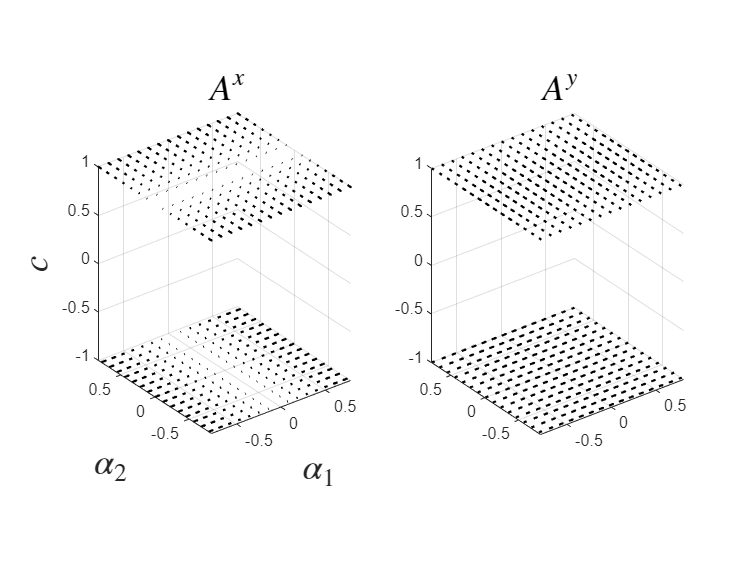

% Let the legs have a 90deg swing range centered about 0
ank = pi/4;

% Define the colors for each contact mode:
circ1 = [215,25,28]*(1/255); 
circ3 = [44,123,182]*(1/255);
circ2 = [96,0,220]*(1/255);

% The 3D shape-space is discretized equally
numD = 15; % if you change individual spacing it will break

% Let's also introduce a contact variable c and stack the vector fields on
% top of each other:
c = linspace(-1,1,numD);

% Discretize the continuous shapes and meshgrid
a1 = linspace(-ank,ank,numD); a2 = a1;
[a1,a2,c] = meshgrid(a1,a2,c); a1 = reshape(a1,1,numel(a1)); a2 = reshape(a2,1,numel(a2));
c = reshape(c,1,numel(c));

%%% UNCOMMENT TO OBTAIN THE VECTOR FIELDS SEPARATELY
% X1U = @(r,a_1,a_2) -r.*sin(a_1);
% X1V = @(r,a_1,a_2) 0.*r.*a_1.*a_2;
% Y1U = @(r,a_1,a_2) r.*cos(a_1);
% Y1V = @(r,a_1,a_2) 0.*r.*a_1.*a_2;
% X2U = @(r,a_1,a_2) 0.*r.*a_1.*a_2;
% X2V = @(r,a_1,a_2) r.*sin(a_2);
% Y2U = @(r,a_1,a_2) 0.*r.*a_1.*a_2;
% Y2V = @(r,a_1,a_2) -r.*cos(a_2);
% x1u = X1U(1,a1,a2); x1v = X1V(1,a1,a2); y1u = Y1U(1,a1,a2); y1v = Y1V(1,a1,a2);
% x2u = X2U(1,a1,a2); x2v = X2V(1,a1,a2); y2u = Y2U(1,a1,a2); y2v = Y2V(1,a1,a2);

% figure()
% subplot(2,2,1) % x vector field of A1
% quiver(a1,a2,x1u,x1v,'k','LineWidth',1.2);
% axis equal tight;
% xlabel('$\alpha_1$','Interpreter','latex',FontSize=20);
% ylabel('$\alpha_2$','Interpreter','latex',FontSize=20);
% title('$A_1^x$','Interpreter','latex',FontSize=20);
% 
% subplot(2,2,3) % y vector field of A1
% quiver(a1,a2,y1u,y1v,'k','LineWidth',1.2);
% axis equal tight;
% title('$A_1^y$','Interpreter','latex',FontSize=20);
% 
% subplot(2,2,2) % x vector field of A2
% quiver(a1,a2,x2u,x2v,'k','LineWidth',1.2);
% axis equal tight;
% title('$A_2^x$','Interpreter','latex',FontSize=20);
% 
% subplot(2,2,4) % y vector field of A2
% quiver(a1,a2,y2u,y2v,'k','LineWidth',1.2);
% axis equal tight;
% title('$A_2^y$','Interpreter','latex',FontSize=20);

% At c=-1 is the first vector field and c=1 is the second vector field
XU = @(r,a_1,a_2,c) -r.*sin(a_1).*(c==-1) + 0.*r.*a_1.*a_2.*(c==1);
XV = @(r,a_1,a_2,c) 0.*r.*a_1.*a_2.*(c==-1) - r.*sin(pi + a_2).*(c==1);
YU = @(r,a_1,a_2,c) r.*cos(a_1).*(c==-1) + 0.*r.*a_1.*a_2.*(c==1);
YV = @(r,a_1,a_2,c) 0.*r.*a_1.*a_2.*(c==-1) + r.*cos(pi + a_2).*(c==1);

xu_1 = XU(1,a1,a2,c); xv_2 = XV(1,a1,a2,c); xw_3 = zeros(size(xv_2));
yu = YU(1,a1,a2,c); yv = YV(1,a1,a2,c); yw = zeros(size(yv));

figure()

subplot(1,2,1)
quiver3(a1,a2,c,xu_1,xv_2,xw_3,'k','LineWidth',1.2);
axis equal tight;
xlabel('$\alpha_1$','Interpreter','latex',FontSize=20);
ylabel('$\alpha_2$','Interpreter','latex',FontSize=20);
zlabel('$c$','Interpreter','latex',FontSize=20);
title('$A^x$','Interpreter','latex',FontSize=20);

subplot(1,2,2)
quiver3(a1,a2,c,yu,yv,yw,'k','LineWidth',1.2);
axis equal tight;
title('$A^y$','Interpreter','latex',FontSize=20);

Next, we shall draw the gait and try to highlight the vector field along the shape-space traverse by the gait; for the sake of simplicity, we consider a gait where equal time is spent between switching and swinging for all legs and contact states considered. Recall that the 

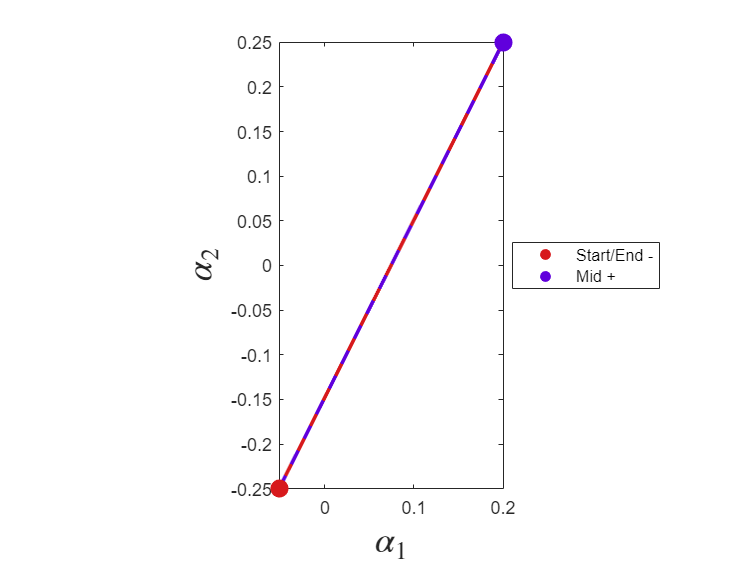

% Now, we can construct arbitrary gaits and run the approximation -- just
% panel 12
temp = [-0.051, 0.20;
   -0.25, 0.25]; % randomized -- (rand(2,2) - 0.5)*ank
phi_0 = temp(:,1); phi_m = temp(:,2);

% Plot the gait in the shape-space of the system
figure()
p1 = plot(temp(1,:),temp(2,:),'LineStyle','-','Color',circ1,'LineWidth',2);
set(get(get(p1,'Annotation'),'LegendInformation'),'IconDisplayStyle','off');
hold on;
p2 = plot(temp(1,:),temp(2,:),'LineStyle','--','Color',circ2,'LineWidth',2);
set(get(get(p2,'Annotation'),'LegendInformation'),'IconDisplayStyle','off');
scatter(phi_0(1),phi_0(2),100,circ1,'filled','DisplayName','Start/End -'); % color matches the first half of the gait
scatter(phi_m(1),phi_m(2),100,circ2,'filled','DisplayName','Mid +'); % midway point for second half
axis equal tight; legend('location','best');
xlabel('$\alpha_1$','Interpreter','latex',FontSize=20);
ylabel('$\alpha_2$','Interpreter','latex',FontSize=20);

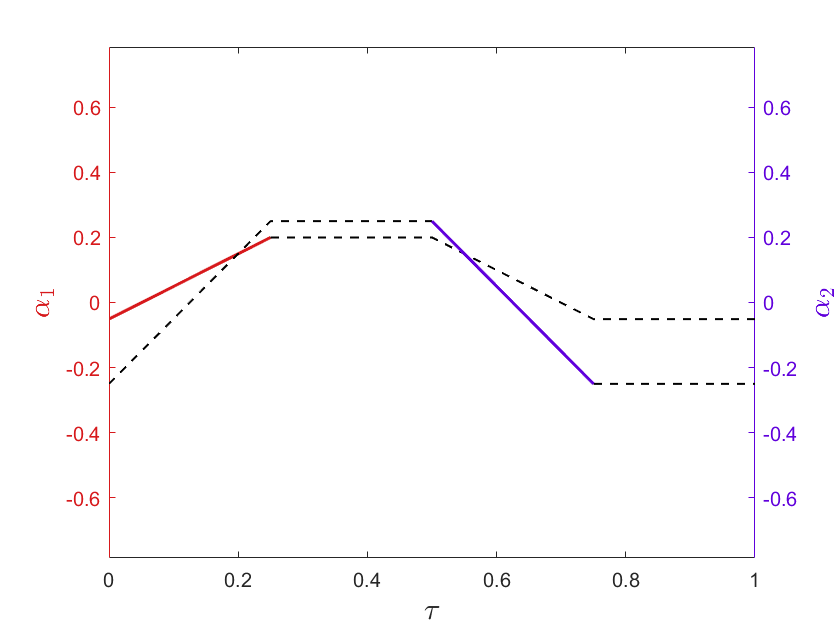

% Number of points to display the vector field for the contact stroke (spans tau for 0.25)
numV = 7;

% Shape change in each direction for the chosen gait
quartg_temp = linspace(phi_0(1),phi_m(1),numV); quartg_temp = quartg_temp(:);
phi_1 = [quartg_temp(:)',quartg_temp(end)*ones(1,numel(quartg_temp)-1),...
    fliplr(quartg_temp(1:end-1)'),quartg_temp(1)*ones(1,numel(quartg_temp)-1)];
quartg_temp = linspace(phi_0(2),phi_m(2),numV); quartg_temp = quartg_temp(:);
phi_2 = [quartg_temp(:)',quartg_temp(end)*ones(1,numel(quartg_temp)-1),...
    fliplr(quartg_temp(1:end-1)'),quartg_temp(1)*ones(1,numel(quartg_temp)-1)];

% Create a time period vector
tau = linspace(0,1,length(phi_1));

% Define the contact state over the gait first
phi_c = zeros(size(tau)); phi_c(tau < 0.25) = -1; 
phi_c(tau >= 0.25 & tau < 0.5) = linspace(-1,1,numel(tau(tau >= 0.25 & tau < 0.5)));
phi_c(tau >= 0.5 & tau < 0.75) = 1; 
phi_c(tau >= 0.75) = linspace(1,-1,numel(tau(tau >= 0.75)));

% Plot the gait as a function of the time-period
figure()
yyaxis left
plot(tau(tau<=0.25), phi_1(tau<=0.25), 'Color', circ1, 'LineStyle', '-', 'LineWidth', 1.5);
hold on;
plot(tau(tau>=0.25), phi_1(tau>=0.25), 'Color', 'k', 'LineStyle', '--', 'LineWidth', 1.0);
ylim([-ank, ank]);
% axis tight;
ylabel('$\alpha_1$','Interpreter','latex','FontSize',15,'Color',circ1);
set(gca,'YColor',circ1);

xlabel('$\tau$','Interpreter','latex','FontSize',15);

yyaxis right
plot(tau(tau<=0.5), phi_2(tau<=0.5), 'Color', 'k', 'LineStyle', '--', 'LineWidth', 1.0);
hold on;
plot(tau(tau>=0.75), phi_2(tau>=0.75), 'Color', 'k', 'LineStyle', '--', 'LineWidth', 1.0);
plot(tau(tau>=0.5 & tau<=0.75), phi_2(tau>=0.5 & tau<=0.75), 'Color', circ2, 'LineStyle', '-', 'LineWidth', 1.5);
ylim([-ank, ank]);
% axis tight;
ylabel('$\alpha_2$','Interpreter','latex','FontSize',15,'Color',circ2);
set(gca,'YColor',circ2);

The contact states are highlighted in their respective colors -- in a contact state, only the leg in contact's shape change matters.

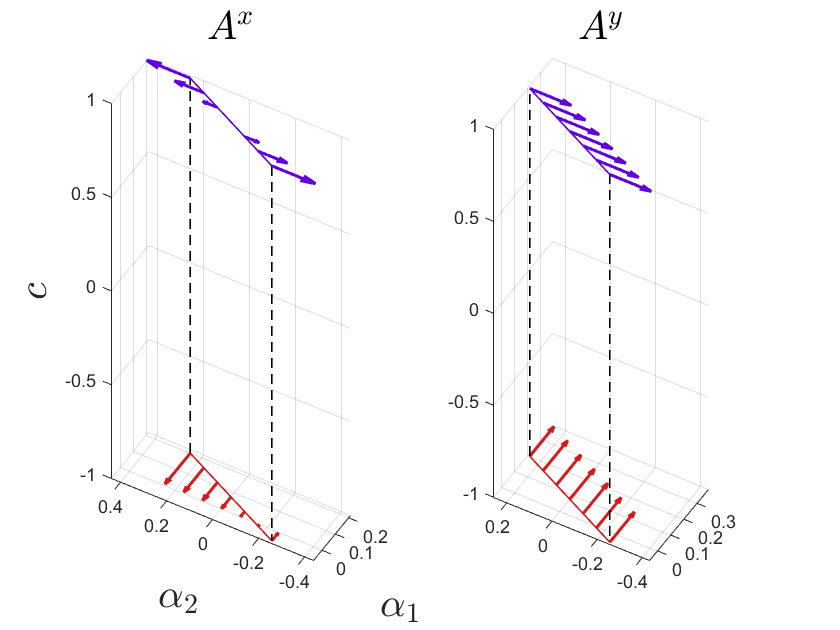

% % Buff percentage and line width for the plotting window:
% buff = 10;
% % Get the limits in each continuous shape axis for plot positioning
% lim1_L = min([phi_0(1),phi_m(1)]); lim1_H = max([phi_0(1),phi_m(1)]); range1 = buff*(lim1_H-lim1_L)/100;
% lim2_L = min([phi_0(2),phi_m(2)]); lim2_H = max([phi_0(2),phi_m(2)]);

qW = 1.5; linW = 0.8;

% Indices to distinguish each vector field
idx1 = (tau <= 0.25); idx2 = (tau >= 0.5 & tau <= 0.75); idxU = (tau>=0.25 & tau<=0.5); idxD = (tau>=0.75 & tau<=1);

% Compute the vector field:
xu_2phi = XU(1,phi_1,phi_2,phi_c); xv_2phi = XV(1,phi_1,phi_2,phi_c); xz_2phi = zeros(size(xv_2phi));
yu_2phi = YU(1,phi_1,phi_2,phi_c); yv_2phi = YV(1,phi_1,phi_2,phi_c); yz_2phi = zeros(size(yv_2phi));

% Now, plot in 3D shape-space:
figure()

azi = -60; elev = 45;

subplot(1,2,1)
quiver3(phi_1(idx1),phi_2(idx1),phi_c(idx1),xu_2phi(idx1),xv_2phi(idx1),xz_2phi(idx1),'Color',circ1,'LineWidth',qW);
axis equal tight; hold on; view(azi,elev);
quiver3(phi_1(idx2),phi_2(idx2),phi_c(idx2),xu_2phi(idx2),xv_2phi(idx2),xz_2phi(idx2),'Color',circ2,'LineWidth',qW);
% quiver3(phi_1(~idx1 & ~idx2),phi_2(~idx1 & ~idx2),phi_c(~idx1 & ~idx2)...
%     ,xu_2phi(~idx1 & ~idx2),xv_2phi(~idx1 & ~idx2),xz_2phi(~idx1 & ~idx2),'k','LineWidth',1.2);
% Now plot the lines:
plot3(phi_1(idx1),phi_2(idx1),phi_c(idx1),'Color',circ1,'LineWidth',linW);
plot3(phi_1(idx2),phi_2(idx2),phi_c(idx2),'Color',circ2,'LineWidth',linW);
plot3(phi_1(idxU),phi_2(idxU),phi_c(idxU),'k--','LineWidth',linW);
plot3(phi_1(idxD),phi_2(idxD),phi_c(idxD),'k--','LineWidth',linW);
xlabel('$\alpha_1$','Interpreter','latex',FontSize=20);
ylabel('$\alpha_2$','Interpreter','latex',FontSize=20);
zlabel('$c$','Interpreter','latex',FontSize=20);
title('$A^x$','Interpreter','latex',FontSize=20);

subplot(1,2,2)
quiver3(phi_1(idx1),phi_2(idx1),phi_c(idx1),yu_2phi(idx1),yv_2phi(idx1),yz_2phi(idx1),'Color',circ1,'LineWidth',qW);
axis equal tight; hold on; view(azi,elev);
quiver3(phi_1(idx2),phi_2(idx2),phi_c(idx2),yu_2phi(idx2),yv_2phi(idx2),yz_2phi(idx2),'Color',circ2,'LineWidth',qW);
plot3(phi_1(idx1),phi_2(idx1),phi_c(idx1),'Color',circ1,'LineWidth',linW);
plot3(phi_1(idx2),phi_2(idx2),phi_c(idx2),'Color',circ2,'LineWidth',linW);
plot3(phi_1(idxU),phi_2(idxU),phi_c(idxU),'k--','LineWidth',linW);
plot3(phi_1(idxD),phi_2(idxD),phi_c(idxD),'k--','LineWidth',linW);
% quiver3(phi_1(~idx1 & ~idx2),phi_2(~idx1 & ~idx2),phi_c(~idx1 & ~idx2)...
%     ,yu_2phi(~idx1 & ~idx2),yv_2phi(~idx1 & ~idx2),yz_2phi(~idx1 & ~idx2),'k','LineWidth',1.2);
title('$A^y$','Interpreter','latex',FontSize=20);

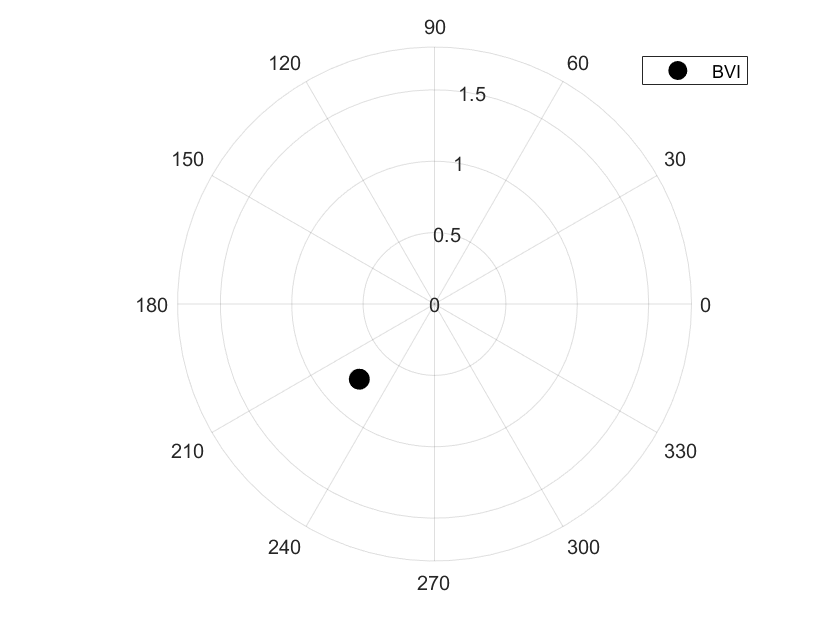

% Let's estimate the displacement through the boundary integral
z_phi_BVI = double(-int(subs(A_1,r,1)*[1; 0], alpha_1, [phi_0(1) phi_m(1)]) -int(subs(A_2,r,1)*[0; 1], alpha_2, [phi_m(2) phi_0(2)]));

% Let's plot this as a phasor:
figure()
polarplot(atan2(z_phi_BVI(2),z_phi_BVI(2)),norm(z_phi_BVI),...
    'ko','MarkerSize',10,'MarkerFaceColor','k','DisplayName','BVI');
legend('Location','best');

Now, we shall plot the switching flux and plot it in the system's shape space **<CHECK NOTES "SINGLE DISK DECOUPLED" FOR ANALYTICAL RESULTS>**. Let's compute the line equation to collapse to the flux face for the given discrete gait.

lineQ = null([temp',  ones(2,1)])

lineQ =     0.8917
   -0.4477
   -0.0664


% Let's introduce the line equation with symbol alpha
syms a b c alpha real % a, b, and c belong to the line equation

% Use the analytical result and substitute the line equation parameters
flux_slice = a/b*[sin(a/b*alpha + c/b); cos(a/b*alpha + c/b)] - [-sin(alpha); cos(alpha)];
flux_slice = subs(flux_slice, [a, b, c], [lineQ(1), lineQ(2), lineQ(3)])

$$flux\_slice = \left(\begin{array}{c} \frac{8032050041201797\,\sin\left(\frac{8032050041201797\,\alpha }{4032089120683304}-\frac{2393550912278135}{16128356482733216}\right)}{4032089120683304}+\sin\left(\alpha \right)\\ -\frac{8032050041201797\,\cos\left(\frac{8032050041201797\,\alpha }{4032089120683304}-\frac{2393550912278135}{16128356482733216}\right)}{4032089120683304}-\cos\left(\alpha \right) \end{array}\right)$$

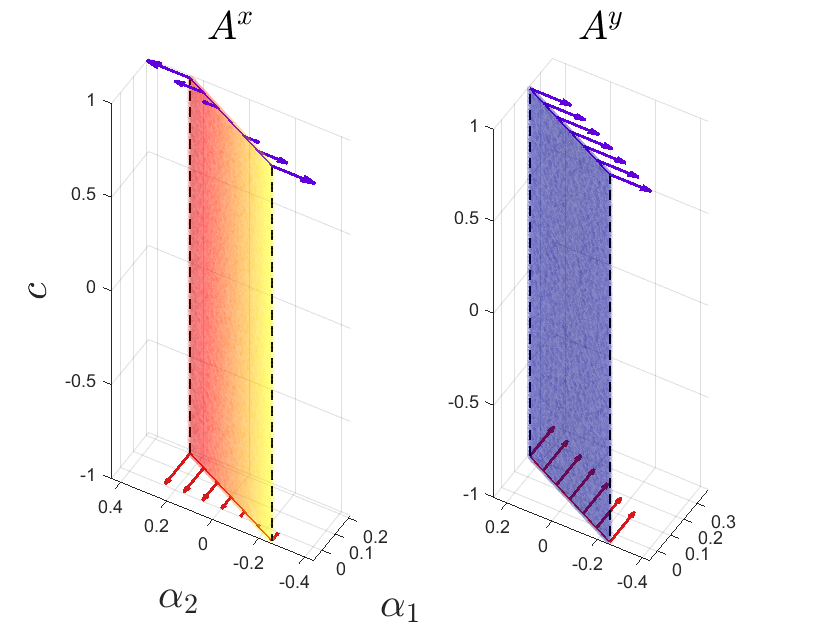

% Convert this into a matlab function
fluxS_X = matlabFunction(flux_slice(1), 'Vars', alpha);
fluxS_Y = matlabFunction(flux_slice(2), 'Vars', alpha);

% Get the switching flux surface parameterized
[A2_fS, C_fS] = meshgrid(linspace(phi_0(2),phi_m(2)),linspace(-1,1));
A1_fS = -lineQ(2)/lineQ(1).*A2_fS -lineQ(3)/lineQ(1);
A1_fS = A1_fS(:); A2_fS = A2_fS(:); C_fS = C_fS(:);

% Compute the slices for each alpha_1 value (or alpha_2 based of b == 0)
fS_X = fluxS_X(A1_fS); fS_Y = fluxS_Y(A1_fS);
fS_X = fS_X(:); fS_Y = fS_Y(:);

% Get the maximum and minimum values for the colorbar:
maxC = max([ceil(max(fS_X,[],'all')), ceil(max(fS_Y,[],'all'))],[],'all');
minC = min([floor(min(fS_X,[],'all')), floor(min(fS_Y,[],'all'))],[],'all');

% Now, plot in 3D shape-space:
figure()

azi = -60; elev = 45;

subplot(1,2,1)
quiver3(phi_1(idx1),phi_2(idx1),phi_c(idx1),xu_2phi(idx1),xv_2phi(idx1),xz_2phi(idx1),'Color',circ1,'LineWidth',qW);
axis equal tight; hold on; view(azi,elev);
quiver3(phi_1(idx2),phi_2(idx2),phi_c(idx2),xu_2phi(idx2),xv_2phi(idx2),xz_2phi(idx2),'Color',circ2,'LineWidth',qW);
plot3(phi_1(idx1),phi_2(idx1),phi_c(idx1),'Color',circ1,'LineWidth',linW);
plot3(phi_1(idx2),phi_2(idx2),phi_c(idx2),'Color',circ2,'LineWidth',linW);
plot3(phi_1(idxU),phi_2(idxU),phi_c(idxU),'k--','LineWidth',linW);
plot3(phi_1(idxD),phi_2(idxD),phi_c(idxD),'k--','LineWidth',linW);
xlabel('$\alpha_1$','Interpreter','latex',FontSize=20);
ylabel('$\alpha_2$','Interpreter','latex',FontSize=20);
zlabel('$c$','Interpreter','latex',FontSize=20);
title('$A^x$','Interpreter','latex',FontSize=20);
% Plot the switching flux using scatter3
scatter3(A1_fS,A2_fS,C_fS,10,fS_X,'filled','MarkerFaceAlpha',0.1,'MarkerEdgeColor','none','Marker','o'); %
colormap(jet); caxis([minC maxC]); % colorbar('ylim',[minC maxC]); 

subplot(1,2,2)
quiver3(phi_1(idx1),phi_2(idx1),phi_c(idx1),yu_2phi(idx1),yv_2phi(idx1),yz_2phi(idx1),'Color',circ1,'LineWidth',qW);
axis equal tight; hold on; view(azi,elev);
quiver3(phi_1(idx2),phi_2(idx2),phi_c(idx2),yu_2phi(idx2),yv_2phi(idx2),yz_2phi(idx2),'Color',circ2,'LineWidth',qW);
plot3(phi_1(idx1),phi_2(idx1),phi_c(idx1),'Color',circ1,'LineWidth',linW);
plot3(phi_1(idx2),phi_2(idx2),phi_c(idx2),'Color',circ2,'LineWidth',linW);
plot3(phi_1(idxU),phi_2(idxU),phi_c(idxU),'k--','LineWidth',linW);
plot3(phi_1(idxD),phi_2(idxD),phi_c(idxD),'k--','LineWidth',linW);
title('$A^y$','Interpreter','latex',FontSize=20);
scatter3(A1_fS,A2_fS,C_fS,10,fS_Y,'filled','MarkerFaceAlpha',0.1,'MarkerEdgeColor','none','Marker','o'); %
colormap(jet); caxis([minC maxC]); % colorbar('ylim',[minC maxC]);

% 
% subplot(1,3,3)
% colormap(jet); sP = colorbar('ylim',[minC maxC],'Position',[0.1,0.1,0.1,0.1]); 
% set(gca,'Visible','off');

Let's figure out the displacement with the Stokes' approximation.

z_phi_sFI = double(int(flux_slice, alpha, [phi_1(1) phi_m(1)]));

Closely matches our BVI as shown below!

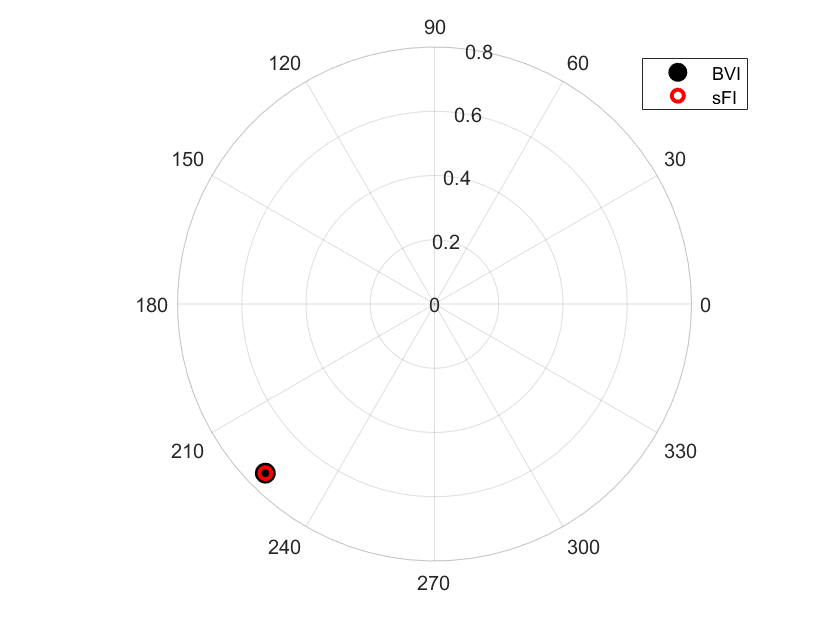

figure()
polarplot(atan2(z_phi_BVI(2),z_phi_BVI(2)),norm(z_phi_BVI),...
    'ko','MarkerSize',10,'MarkerFaceColor','k','DisplayName','BVI');
hold on;
polarplot(atan2(z_phi_sFI(2),z_phi_sFI(2)),norm(z_phi_sFI),...
    'ro','LineWidth',2,'MarkerFaceColor','none','DisplayName','sFI');
legend('Location','best');

Alright, now we can finally animate the system with its trajectory per gait cycle shown.

## Animation (without fanimator)

% Let's increase the resolution on our gait time-series
numV = 25;
quartg_temp = linspace(phi_0(1),phi_m(1),numV); quartg_temp = quartg_temp(:);
phi_1 = [quartg_temp(:)',quartg_temp(end)*ones(1,numel(quartg_temp)-1),...
    fliplr(quartg_temp(1:end-1)'),quartg_temp(1)*ones(1,numel(quartg_temp)-1)];
quartg_temp = linspace(phi_0(2),phi_m(2),numV); quartg_temp = quartg_temp(:);
phi_2 = [quartg_temp(:)',quartg_temp(end)*ones(1,numel(quartg_temp)-1),...
    fliplr(quartg_temp(1:end-1)'),quartg_temp(1)*ones(1,numel(quartg_temp)-1)];
tau = linspace(0,1,length(phi_1));
phi_c = zeros(size(tau)); phi_c(tau < 0.25) = -1; 
phi_c(tau >= 0.25 & tau < 0.5) = linspace(-1,1,numel(tau(tau >= 0.25 & tau < 0.5)));
phi_c(tau >= 0.5 & tau < 0.75) = 1; 
phi_c(tau >= 0.75) = linspace(1,-1,numel(tau(tau >= 0.75)));

% We shall use fanimator for this section -- this will be the boundary
% integral method.
syms x y theta

% Let's obtain some indices that will be useful later on:
idx1 = (tau == 0.25);
idx2s = (tau == 0.5);
idx2 = (tau == 0.75);

% Leg resting position vector length:
lr = 0.5;

% Compute the leg-tip positions and leg-base positions LOCALLY
leg_1 = matlabFunction(subs(r*[cos(alpha_1); sin(alpha_1)],r,1), 'Vars', alpha_1);
leg_2 = matlabFunction(subs(-r*[cos(alpha_2); sin(alpha_2)],r,1), 'Vars', alpha_2);
leg_1r = double(subs(r*[cos(alpha_1); sin(alpha_1)],[r, alpha_1],[lr, 0])); % direction when each leg is unactuated (leg resting position)
leg_2r = double(subs(-r*[cos(alpha_2); sin(alpha_2)],[r, alpha_2],[lr, 0])); 

% Get the COM location and leg locations defined above as a function of time:
Xcm = zeros(size(tau)); Ycm = Xcm;
L1_x = Xcm; L2_x = L1_x; L1_y = L2_x; L2_y = L1_y;
L1r_x = Xcm; L2r_x = L1r_x; L1r_y = L2r_x; L2r_y = L1r_y;

for i = 1:numel(Xcm)

    % COMPUTE COM:
    % ~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~
    if (tau(i) < 0.25) % contact state 1
        
        % Compute the system translation:
        Xcm(i) = -double(int(subs(A_1(1,1),r,1), alpha_1, [phi_1(1) phi_1(i)]));
        Ycm(i) = -double(int(subs(A_1(2,1),r,1), alpha_1, [phi_1(1) phi_1(i)]));

    elseif (tau(i) >= 0.25) && (tau(i) < 0.50) % switching

        % Compute the translations at the end of the first contact phase:
        if tau(i) == 0.25
            Xcm(i) = -double(int(subs(A_1(1,1),r,1), alpha_1, [phi_1(1) phi_1(i)]));
            Ycm(i) = -double(int(subs(A_1(2,1),r,1), alpha_1, [phi_1(1) phi_1(i)]));
        else
            % Substitute the computation at the end of the first contact phase
            Xcm(i) = Xcm(idx1);
            Ycm(i) = Ycm(idx1);
        end

    elseif (tau(i) >= 0.50) && (tau(i) < 0.75) % contact state 2

        Xcm(i) = Xcm(idx1) + -double(int(subs(A_2(1,2),r,1), alpha_2, [phi_1(idx2s) phi_1(i)]));
        Ycm(i) = Ycm(idx1) + -double(int(subs(A_2(2,2),r,1), alpha_2, [phi_2(idx2s) phi_2(i)]));

    else % switching
        
        if tau(i) == 0.75
            Xcm(i) = Xcm(idx1) + -double(int(subs(A_2(1,2),r,1), alpha_2, [phi_1(idx2s) phi_1(i)]));
            Ycm(i) = Ycm(idx1) + -double(int(subs(A_2(2,2),r,1), alpha_2, [phi_2(idx2s) phi_2(i)]));
        else
            Xcm(i) = Xcm(idx2);
            Ycm(i) = Ycm(idx2);
        end

    end
    % ~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~
    % COMPUTE THE LEG POSITIONS GLOBALLY
    
    L1_x(i) = Xcm(i) + [1,0]*leg_1(phi_1(i));
    L1_y(i) = Ycm(i) + [0,1]*leg_1(phi_1(i));
    L2_x(i) = Xcm(i) + [1,0]*leg_2(phi_2(i));
    L2_y(i) = Ycm(i) + [0,1]*leg_2(phi_2(i));

    L1r_x(i) = Xcm(i) + [1,0]*leg_1r;
    L1r_y(i) = Ycm(i) + [0,1]*leg_1r;
    L2r_x(i) = Xcm(i) + [1,0]*leg_2r;
    L2r_y(i) = Ycm(i) + [0,1]*leg_2r;

end

Now, we have all values computed for plotting:

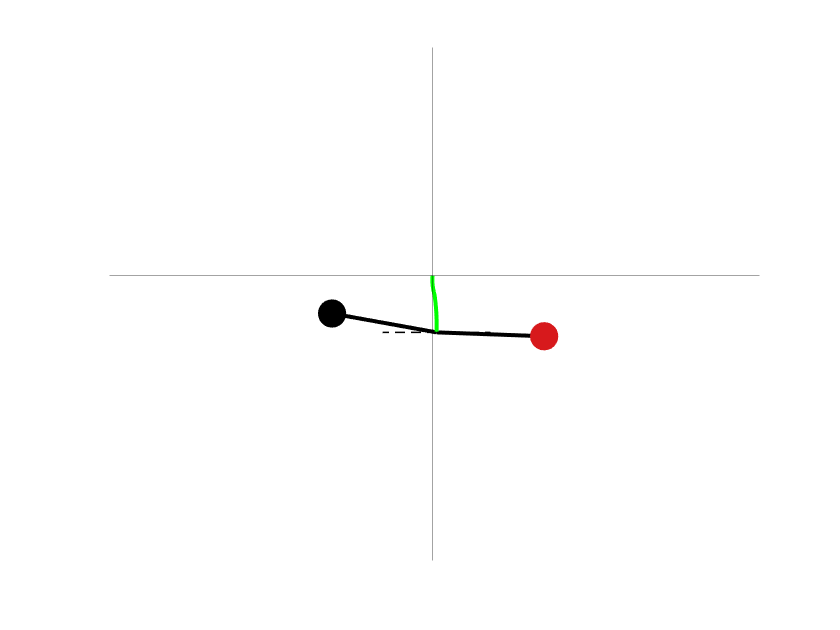

% Get the plot parameters
lW = 2; lW_r = 0.8; circS = 200;
lW_O = 0.5; alp_O = 0.2;
lW_traj = 2;
legL = 1; mulL = 3;

% Get the figure limit
limX = [min(Xcm,[],'all') - mulL*legL, max(Xcm,[],'all') + mulL*legL]; % add the leg length on either side
limY = [min(Ycm,[],'all') - mulL*legL, max(Ycm,[],'all') + mulL*legL];

% Plot the results in a loop
figure()
for i = 1:numel(tau)
    
    % If it is not the final frame, clear it:
    if i ~= numel(tau)
        clf;
    end

    % Plot the legs 
    plot([Xcm(i) L1_x(i)], [Ycm(i) L1_y(i)], 'k', 'LineWidth', lW);
    hold on; set(gca, 'visible', 'off');
    plot([Xcm(i) L2_x(i)], [Ycm(i) L2_y(i)], 'k', 'LineWidth', lW);

    % Plot the origin with thin gray lines
    xline(0,'k','LineWidth',lW_O,'Alpha',0.2); yline(0,'k','LineWidth',lW_O,'Alpha',alp_O);

    % Plot the trajectory:
    plot(Xcm(1:i), Ycm(1:i), 'g', 'LineWidth', lW_traj);
    
    % Plot the leg resting positions
    plot([Xcm(i) L1r_x(i)], [Ycm(i) L1r_y(i)], 'k--', 'LineWidth', lW_r);
    plot([Xcm(i) L2r_x(i)], [Ycm(i) L2r_y(i)], 'k--', 'LineWidth', lW_r);

    % Scatter circle to the leg tips
    scatter(L1_x(i), L1_y(i), circS, interp1([-1,1],[circ1; 0,0,0],phi_c(i)),'filled'); % interpolate between the legs color and black
    scatter(L2_x(i), L2_y(i), circS, interp1([-1,1],[0,0,0; circ2],phi_c(i)),'filled');

    % Set the figure limits:
    xlim(limX); ylim(limY);
    
    % Output the plot:
    drawnow();
end

The natural next step is, how does this extend to a similar three-legged system?

%%%% TEXT: Considering the difference between the vector fields for infinitesimal discrete gaits, we can draw a heat-map that signifies the maximum displacement and plots it out for us. <CHECK NOTES: Compliant Bodied Legged Systems/GM theory/2-legged Single Disk>
% % We need to compute a simplification for finding the average displacement
% % to a orientation independent infinitesimal loop
% syms epsilon alpha theta real
% intg = (1/epsilon)*[-cos(alpha_1 + alpha*epsilon*cos(theta))/cos(theta) + cos(alpha_2 + alpha*epsilon*sin(theta))/sin(theta);
%                     -sin(alpha_1 + alpha*epsilon*cos(theta))/cos(theta) + sin(alpha_2 + alpha*epsilon*sin(theta))/sin(theta)]
% temp = subs(intg,alpha,1) - subs(intg,alpha,-1); 
% intg = simplify(temp,'Steps',50)
% intg = limit(intg,epsilon,0)
%%%% TEXT: Works out to 2( A_2^{(2)}) - A_1^{(1)}) ) as expected for a positive infinitesimal discrete gait! The superscripts denote the corresponding columns involved in the operation. Let's compute this and plot it as a heatmap for each for displacement in X and Y respectively.
% % Let's plot the heatmap - use a 2D discretization (`_2' respresents that)
% a1_2 = reshape(a1(c == -1),numD,numD); a2_2 = reshape(a2(c == -1),numD,numD);
% 
% % Heat
% Xdisp = 2*reshape(xv_2(c == 1) - xu_1(c == -1),numD,numD); Ydisp = 2*reshape(yv(c == 1) - yu(c == -1),numD,numD);
% 
% % Let's get the color limits:
% maxL = max([max(Xdisp,[],'all'), max(Ydisp,[],'all')]);
% minL = min([min(Xdisp,[],'all'), min(Ydisp,[],'all')]);
% 
% % Plot the results:
% figure()
% 
% subplot(1,2,1)
% surf(a1_2,a2_2,Xdisp,'EdgeColor','none'); 
% view(2);
% axis equal tight;
% colormap(jet); 
% colorbar('ylim',[round(min(Xdisp,[],'all')), round(max(Xdisp,[],'all'))]);
% caxis([minL maxL]);
% xlabel('$\alpha_1$','Interpreter','latex',FontSize=20);
% ylabel('$\alpha_2$','Interpreter','latex',FontSize=20);
% title('$dz_{\{\phi_{12}\}}^{x}$','Interpreter','latex',FontSize=20);
% 
% subplot(1,2,2)
% surf(a1_2,a2_2,Ydisp,'EdgeColor','none');
% view(2);
% axis equal tight;
% colormap(jet); 
% colorbar('ylim',[round(min(Ydisp,[],'all')), round(max(Ydisp,[],'all'))]); 
% caxis([minL maxL]);
% title('$dz_{\{\phi_{12}\}}^{y}$','Interpreter','latex',FontSize=20)
%%%% TEXT: Now, we can superimpose this as a slight transparent vector
%%%% cloud onto our disjointed vector field to give a sense of how to draw
%%%% these discrete gaits. 
% % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % NOT REQUIRED!!!!!!!!!!!!!
% % Create the 3D version of the heatmap:
% Xdisp_3 = reshape(repmat(Xdisp,1,1,numD),1,numel(Xdisp)*numD); Ydisp_3 = reshape(repmat(Ydisp,1,1,numD),1,numel(Ydisp)*numD);
% 
% % Plot the vector field again:
% figure()
% 
% h1 = subplot(1,2,1);
% quiver3(a1,a2,c,xu,xv,xz,'k','LineWidth',1.2);
% axis equal tight; hold on;
% scatter3(a1,a2,c,100,Xdisp_3,'filled','MarkerFaceAlpha',0.2,'MarkerEdgeColor','none','Marker','o');
% colormap(jet); 
% % colorbar('peer',h1,'east','Location','eastoutside'); 
% caxis([minL maxL]);
% % xlabel('$\alpha_1$','Interpreter','latex',FontSize=20);
% % ylabel('$\alpha_2$','Interpreter','latex',FontSize=20);
% zlabel('$c$','Interpreter','latex',FontSize=20);
% title('$A^x$','Interpreter','latex',FontSize=20);
% 
% h2 = subplot(1,2,2);
% quiver3(a1,a2,c,yu,yv,yz,'k','LineWidth',1.2);
% axis equal tight; hold on;
% scatter3(a1,a2,c,100,Ydisp_3,'filled','MarkerFaceAlpha',0.2,'MarkerEdgeColor','none','Marker','o');
% colormap(jet); 
% % colorbar('peer',h2,'east','Location','eastoutside'); 
% caxis([minL maxL]);
% title('$A^y$','Interpreter','latex',FontSize=20);

## Three-legged system

Since it is a single-disk system, let's evenly distribute the legs around a circle.

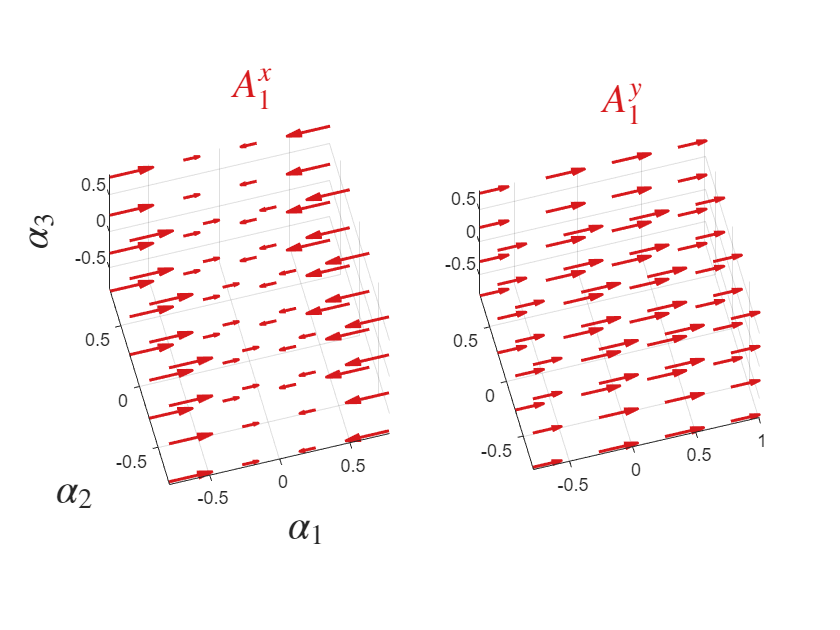

% Number of legs:
numL = 3;

% Leg angle offset from each other:
off = mean(diff(linspace(0,2*pi,numL+1)));

% Let the legs have a 90deg swing range centered about 0
ank = pi/4;

% The 3D shape-space is discretized equally
numD = 4; % if you change individual spacing it will break

% Let the leg length be 1 unit:
r = 1;

% Discretize the continuous shapes and meshgrid
a1 = linspace(-ank,ank,numD); a2 = a1; a3 = a1;
[a1,a2,a3] = meshgrid(a1,a2,a3);
a1 = reshape(a1,1,numel(a1)); a2 = reshape(a2,1,numel(a2)); a3 = reshape(a3,1,numel(a3));

% Directly define the vector field
XU_1 = @(r,a_1,a_2,a_3) -r.*sin(0*off*ones(size(a_2)) + a_1) + 0.*r.*a_1.*a_2.*a_3;
XV_2 = @(r,a_1,a_2,a_3) - r.*sin(1*off*ones(size(a_2)) + a_2) + 0.*r.*a_1.*a_2.*a_3;
XW_3 = @(r,a_1,a_2,a_3) - r.*sin(2*off*ones(size(a_2)) + a_3) + 0.*r.*a_1.*a_2.*a_3;

YU_1 = @(r,a_1,a_2,a_3) r.*cos(0*off*ones(size(a_2)) + a_1) + 0.*r.*a_1.*a_2.*a_3;
YV_2 = @(r,a_1,a_2,a_3) r.*cos(1*off*ones(size(a_2)) + a_2) + 0.*r.*a_1.*a_2.*a_3;
YW_3 = @(r,a_1,a_2,a_3) r.*cos(2*off*ones(size(a_2)) + a_3) + 0.*r.*a_1.*a_2.*a_3;

% Get the data:
xu_1 = XU_1(r,a1,a2,a3); xv_2 = XV_2(r,a1,a2,a3); xw_3 = XW_3(r,a1,a2,a3);
yu_1 = YU_1(r,a1,a2,a3); yv_2 = YV_2(r,a1,a2,a3); yw_3 = YW_3(r,a1,a2,a3);

% Vector field line thickness:
qW = 1.5;

% Define the colors for each contact mode:
circ1 = [215,25,28]*(1/255); 
circ3 = [44,123,182]*(1/255);
circ2 = [96,0,220]*(1/255);

% PLOT THE VECTOR FIELDS
figure()

% in degs
azi_1 = -15; elv_1 = 60;

subplot(1,2,1)
quiver3(a1,a2,a3,xu_1,zeros(size(xu_1)),zeros(size(xu_1)),'Color',circ1,'LineWidth',qW);
axis equal tight; view(azi_1,elv_1);
xlabel('$\alpha_1$','Interpreter','latex',FontSize=20);
ylabel('$\alpha_2$','Interpreter','latex',FontSize=20);
zlabel('$\alpha_3$','Interpreter','latex',FontSize=20);
title('$A_1^x$','Interpreter','latex','Color',circ1,FontSize=20);

subplot(1,2,2)
quiver3(a1,a2,a3,yu_1,zeros(size(yu_1)),zeros(size(yu_1)),'Color',circ1,'LineWidth',qW);
axis equal tight; view(azi_1,elv_1);
title('$A_1^y$','Interpreter','latex','Color',circ1,FontSize=20);

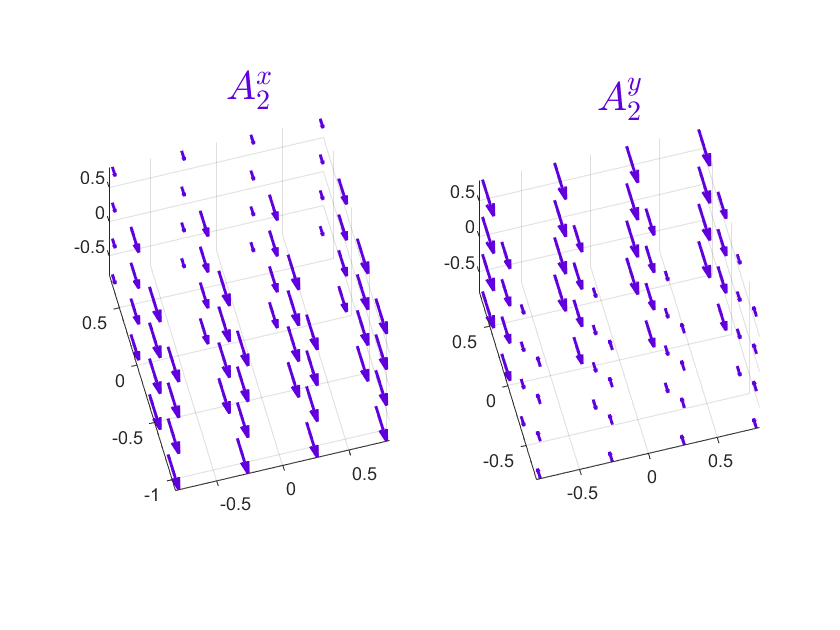

% in degs
azi_2 = -15; elv_2 = 60;

figure()

subplot(1,2,1)
quiver3(a1,a2,a3,zeros(size(xv_2)),xv_2,zeros(size(xv_2)),'Color',circ2,'LineWidth',qW);
axis equal tight; view(azi_2,elv_2);
title('$A_2^x$','Interpreter','latex','Color',circ2,FontSize=20);

subplot(1,2,2)
quiver3(a1,a2,a3,zeros(size(yv_2)),yv_2,zeros(size(yv_2)),'Color',circ2,'LineWidth',qW);
axis equal tight; view(azi_2,elv_2);
title('$A_2^y$','Interpreter','latex','Color',circ2,FontSize=20);

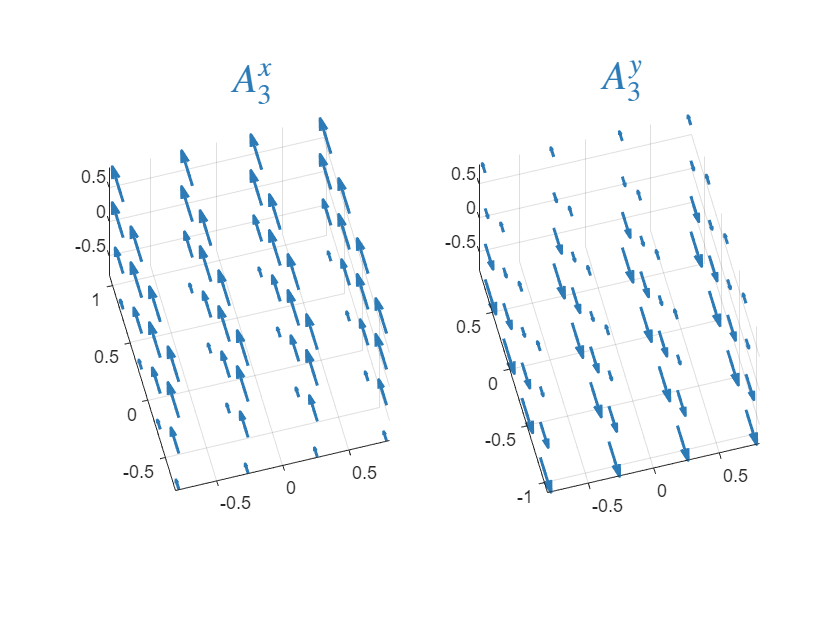

% in degs
azi_3 = -15; elv_3 = 60;

figure()

subplot(1,2,1)
quiver3(a1,a2,a3,zeros(size(xw_3)),xw_3,zeros(size(xw_3)),'Color',circ3,'LineWidth',qW);
axis equal tight; view(azi_3,elv_3);
title('$A_3^x$','Interpreter','latex','Color',circ3,FontSize=20);

subplot(1,2,2)
quiver3(a1,a2,a3,zeros(size(yw_3)),yw_3,zeros(size(yw_3)),'Color',circ3,'LineWidth',qW);
axis equal tight; view(azi_3,elv_3);
title('$A_3^y$','Interpreter','latex','Color',circ3,FontSize=20);

% %%%% TEXT: Now, we can take the difference to obtain the infinitesimal displacement heat-maps.
% % Get the data for a different discretization:
% numD = 15;
% a1 = linspace(-ank,ank,numD); a2 = a1; a3 = a1;
% [a1,a2,a3] = meshgrid(a1,a2,a3);
% a1 = reshape(a1,1,numel(a1)); a2 = reshape(a2,1,numel(a2)); a3 = reshape(a3,1,numel(a3));
% xu_1 = XU_1(r,a1,a2,a3); xv_2 = XV_2(r,a1,a2,a3); xw_3 = XW_3(r,a1,a2,a3);
% yu_1 = YU_1(r,a1,a2,a3); yv_2 = YV_2(r,a1,a2,a3); yw_3 = YW_3(r,a1,a2,a3);
% 
% % Get the indicies for each plot
% idx12 = a3 == ank; idx13 = a2 == ank; idx23 = a1 == ank;
% % Shape-space 3D
% a1_12 = reshape(a1(idx12),numD,numD); a2_12 = reshape(a2(idx12),numD,numD);
% a2_23 = reshape(a2(idx23),numD,numD); a3_23 = reshape(a3(idx23),numD,numD);
% a1_13 = reshape(a1(idx13),numD,numD); a3_13 = reshape(a3(idx13),numD,numD);
% 
% % Heat-Map 3D
% Xdisp_12 = 2*reshape(xv_2(idx12) - xu_1(idx12),numD,numD); 
% Ydisp_12 = 2*reshape(yv_2(idx12) - yu_1(idx12),numD,numD);
% 
% Xdisp_23 = 2*reshape(xv_2(idx23) - xu_1(idx23),numD,numD); 
% Ydisp_23 = 2*reshape(yv_2(idx23) - yu_1(idx23),numD,numD);
% 
% Xdisp_13 = 2*reshape(xw_3(idx13) - xu_1(idx13),numD,numD); 
% Ydisp_13 = 2*reshape(yw_3(idx13) - yu_1(idx13),numD,numD);
% 
% % Let's get the color limits:
% maxL_12 = max([max(Xdisp_12,[],'all'), max(Ydisp_12,[],'all')]);
% minL_12 = min([min(Xdisp_12,[],'all'), min(Ydisp_12,[],'all')]);
% maxL_23 = max([max(Xdisp_23,[],'all'), max(Ydisp_23,[],'all')]);
% minL_23 = min([min(Xdisp_23,[],'all'), min(Ydisp_23,[],'all')]);
% maxL_13 = max([max(Xdisp_13,[],'all'), max(Ydisp_13,[],'all')]);
% minL_13 = min([min(Xdisp_13,[],'all'), min(Ydisp_13,[],'all')]);
% 
% % Decimal places to round off for the colorbar
% decB = 2;
% 
% % Plot the results:
% figure()
% 
% subplot(3,2,1)
% surf(a1_12,a2_12,Xdisp_12,'EdgeColor','none');
% axis equal tight; hold on; view(2);
% colormap(jet); caxis([minL_12 maxL_12]);
% colorbar('ylim',[round(min(Xdisp_12,[],'all'),decB), round(max(Xdisp_12,[],'all'),decB)]);
% xlabel('$\alpha_1$','Interpreter','latex',FontSize=20);
% ylabel('$\alpha_2$','Interpreter','latex',FontSize=20);
% title('$dz_{\{\phi_{12}\}}^{x}$','Interpreter','latex',FontSize=20);
% 
% subplot(3,2,2)
% surf(a1_12,a2_12,Ydisp_12,'EdgeColor','none');
% axis equal tight; hold on; view(2);
% colormap(jet); caxis([minL_12 maxL_12]);
% colorbar('ylim',[round(min(Ydisp_12,[],'all'),decB), round(max(Ydisp_12,[],'all'),decB)]);
% title('$dz_{\{\phi_{12}\}}^{y}$','Interpreter','latex',FontSize=20);
% 
% subplot(3,2,3)
% surf(a2_23,a3_23,Xdisp_23,'EdgeColor','none');
% axis equal tight; hold on; view(2);
% colormap(jet); caxis([minL_23 maxL_23]);
% colorbar('ylim',[round(min(Xdisp_23,[],'all'),decB), round(max(Xdisp_23,[],'all'),decB)]);
% xlabel('$\alpha_2$','Interpreter','latex',FontSize=20);
% ylabel('$\alpha_3$','Interpreter','latex',FontSize=20);
% title('$dz_{\{\phi_{23}\}}^{x}$','Interpreter','latex',FontSize=20);
% 
% subplot(3,2,4)
% surf(a2_23,a3_23,Ydisp_23,'EdgeColor','none');
% axis equal tight; hold on; view(2);
% colormap(jet); caxis([minL_23 maxL_23]);
% colorbar('ylim',[round(min(Ydisp_23,[],'all'),decB), round(max(Ydisp_23,[],'all'),decB)]);
% title('$dz_{\{\phi_{23}\}}^{y}$','Interpreter','latex',FontSize=20);
% 
% subplot(3,2,5)
% surf(a1_13,a3_13,Xdisp_13,'EdgeColor','none');
% axis equal tight; hold on; view(2);
% colormap(jet); caxis([minL_13 maxL_13]);
% colorbar('ylim',[round(min(Xdisp_13,[],'all'),decB), round(max(Xdisp_13,[],'all'),decB)]);
% xlabel('$\alpha_1$','Interpreter','latex',FontSize=20);
% ylabel('$\alpha_3$','Interpreter','latex',FontSize=20);
% title('$dz_{\{\phi_{13}\}}^{x}$','Interpreter','latex',FontSize=20);
% 
% subplot(3,2,6)
% surf(a1_13,a3_13,Ydisp_13,'EdgeColor','none');
% axis equal tight; hold on; view(2);
% colormap(jet); caxis([minL_13 maxL_13]);
% colorbar('ylim',[round(min(Ydisp_13,[],'all'),decB), round(max(Ydisp_13,[],'all'),decB)]);
% title('$dz_{\{\phi_{13}\}}^{y}$','Interpreter','latex',FontSize=20);

## Extending Stokes' theorem

In this section, the focus is on extending switching flux framework to legs decoupled systems we care about. Since the system we consider is conservative, we only consider straight-line paths in each connection vector field.

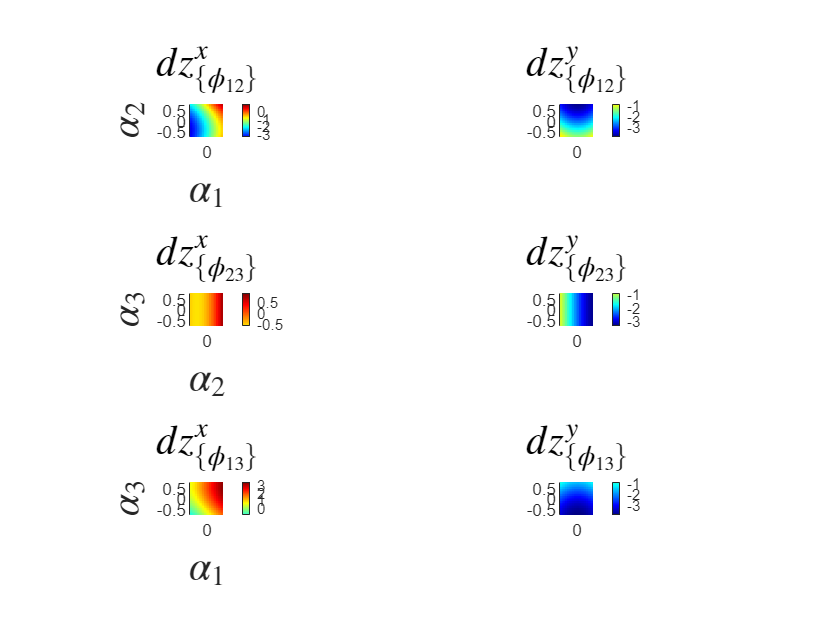

% Let's redefine the ankle limits for the three legged system:

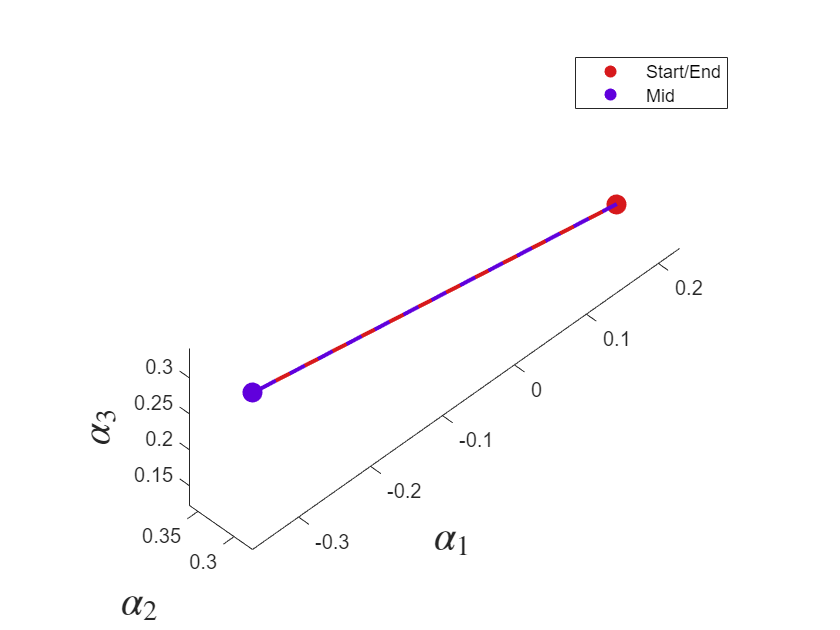

ank = pi/4;

% Number of legs:
numL = 3;

% Define the colors for each contact mode:
circ1 = [215,25,28]*(1/255); 
circ3 = [44,123,182]*(1/255);
circ2 = [96,0,220]*(1/255);

% Leg angle offset from each other:
off = mean(diff(linspace(0,2*pi,numL+1)));

% Define each vector field for the three contact case -- the vector fields
% are irrotational and hence only translations are considered
syms r alpha_1 alpha_2 alpha_3 real

A_1 = r*[-sin(alpha_1 + off*0), 0, 0;
        cos(alpha_1 + off*0), 0, 0;
        0, 0, 0]; % added alpha_2 and alpha_3 to get the matlabFunction to work properly

A_2 = r*[0, -sin(alpha_2 + off*1), 0;
        0, cos(alpha_2 + off*1), 0;
        0, 0, 0];

A_3 = r*[0, 0, -sin(alpha_3 + off*2);
        0, 0, cos(alpha_3 + off*2);
        0, 0, 0];

% Let's create a matlab function for connection vector field:
A1f = matlabFunction(A_1,'Vars',[r alpha_1 alpha_2 alpha_3]);
A2f = matlabFunction(A_2,'Vars',[r alpha_1 alpha_2 alpha_3]);
A3f = matlabFunction(A_3,'Vars',[r alpha_1 alpha_2 alpha_3]);

% Get the analytical form of the switching flux
dz_12_x = matlabFunction(2*(A_2(1,2) - A_1(1,1)),'Vars',[r alpha_1 alpha_2 alpha_3]);
dz_12_y = matlabFunction(2*(A_2(2,2) - A_1(2,1)),'Vars',[r alpha_1 alpha_2 alpha_3]);

dz_23_x = matlabFunction(2*(A_3(1,3) - A_2(1,2)),'Vars',[r alpha_1 alpha_2 alpha_3]);
dz_23_y = matlabFunction(2*(A_3(2,3) - A_2(2,2)),'Vars',[r alpha_1 alpha_2 alpha_3]);

dz_13_x = matlabFunction(2*(A_3(1,3) - A_1(1,1)),'Vars',[r alpha_1 alpha_2 alpha_3]);
dz_13_y = matlabFunction(2*(A_3(2,3) - A_1(2,1)),'Vars',[r alpha_1 alpha_2 alpha_3]);

% Create a 3D grid of the shape space
[a1,a2,a3] = meshgrid(linspace(-ank,ank),linspace(-ank,ank),linspace(-ank,ank));

% Evaluate the sf12

% Now, we can construct arbitrary gaits and run the approximation -- just
% panel 12
temp = [0.2295,   -0.3647;
        0.3609,    0.2742;
        0.1223,    0.3409]; % randomized -- (rand(3,2) - 0.5)*ank
phi_0 = temp(:,1); phi_m = temp(:,2);

% Plot the gait in the shape-space of the system
azi = -45; elv = 45;
figure()
p1 = plot3(temp(1,:),temp(2,:),temp(3,:),'LineStyle','-','Color',circ1,'LineWidth',2);
set(get(get(p1,'Annotation'),'LegendInformation'),'IconDisplayStyle','off');
hold on;
p2 = plot3(temp(1,:),temp(2,:),temp(3,:),'LineStyle','--','Color',circ2,'LineWidth',2);
set(get(get(p2,'Annotation'),'LegendInformation'),'IconDisplayStyle','off');
scatter3(phi_0(1),phi_0(2),phi_0(3),100,circ1,'filled','DisplayName','Start/End'); % color matches the first half of the gait
scatter3(phi_m(1),phi_m(2),phi_m(3),100,circ2,'filled','DisplayName','Mid'); % midway point for second half
axis equal tight; view(azi,elv); legend('location','best');
xlabel('$\alpha_1$','Interpreter','latex',FontSize=20);
ylabel('$\alpha_2$','Interpreter','latex',FontSize=20);
zlabel('$\alpha_3$','Interpreter','latex',FontSize=20);
% Plot the same system in the switching flux for 12
idx12 = (a3 == ank);
maxL_12 = max([max(dz_12_x(1,a1(idx12),a2(idx12),a3(idx12)),[],'all'),...
    max(dz_12_y(1,a1(idx12),a2(idx12),a3(idx12)),[],'all')]);

minL_12 = min([min(dz_12_x(1,a1(idx12),a2(idx12),a3(idx12)),[],'all'),...
    min(dz_12_y(1,a1(idx12),a2(idx12),a3(idx12)),[],'all')]);

decB = 2;

figure()

subplot(1,2,1)
surf(reshape(a1(idx12),100,100),reshape(a2(idx12),100,100),...
    reshape(dz_12_x(1,a1(idx12),a2(idx12),a3(idx12)),100,100),'EdgeColor','none');
axis equal tight; hold on; view(2);
plot3(temp(1,:),temp(2,:),temp(3,:),'LineStyle','-','Color',circ1,'LineWidth',2);
scatter3(phi_0(1),phi_0(2),phi_0(3),100,circ1,'filled');
scatter3(phi_m(1),phi_m(2),phi_m(3),100,circ2,'filled');
colormap(jet); caxis([minL_12 maxL_12]);
colorbar('ylim',[round(min(dz_12_x(1,a1(idx12),a2(idx12),a3(idx12)),[],'all'),decB),...
    round(max(dz_12_y(1,a1(idx12),a2(idx12),a3(idx12)),[],'all'),decB)]);
xlabel('$\alpha_1$','Interpreter','latex',FontSize=20);
ylabel('$\alpha_2$','Interpreter','latex',FontSize=20);
title('$dz_{\{\phi_{12}\}}^{x}$','Interpreter','latex',FontSize=20);

subplot(1,2,2)
surf(reshape(a1(idx12),100,100),reshape(a2(idx12),100,100),...
    reshape(dz_12_y(1,a1(idx12),a2(idx12),a3(idx12)),100,100),'EdgeColor','none');
axis equal tight; hold on; view(2);
plot3(temp(1,:),temp(2,:),temp(3,:),'LineStyle','-','Color',circ1,'LineWidth',2);
scatter3(phi_0(1),phi_0(2),phi_0(3),100,circ1,'filled');
scatter3(phi_m(1),phi_m(2),phi_m(3),100,circ2,'filled');
colormap(jet); caxis([minL_12 maxL_12]);
colorbar('ylim',[round(min(dz_12_y(1,a1(idx12),a2(idx12),a3(idx12)),[],'all'),decB),...
    round(max(dz_12_y(1,a1(idx12),a2(idx12),a3(idx12)),[],'all'),decB)]);
title('$dz_{\{\phi_{12}\}}^{y}$','Interpreter','latex',FontSize=20);

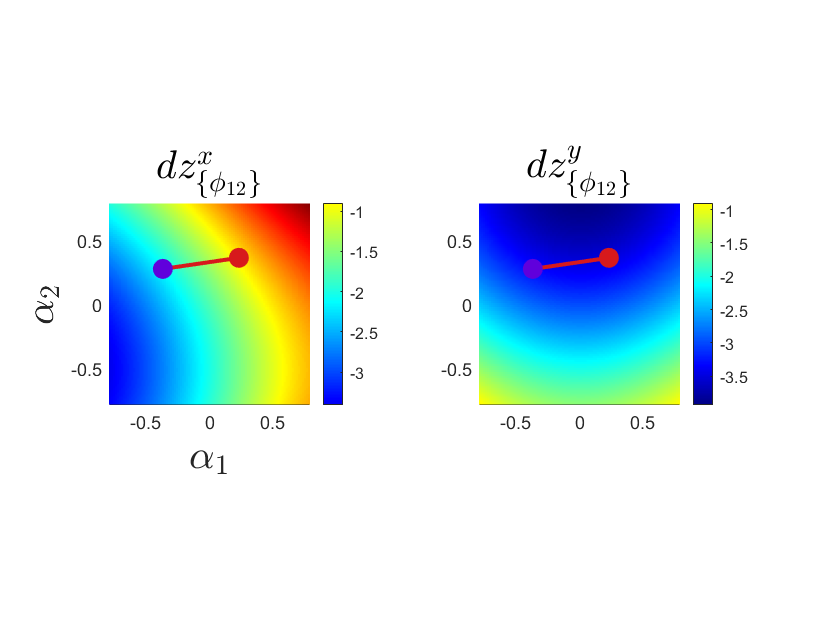

%%%%%% TEXT: Let's now numerically compute the net displacement!
% wid = mean(diff(linspace(phi_0(1),phi_m(1))));
% dz_12_xN = dz_12_x(1,linspace(phi_0(1,1),phi_m(1,1)),linspace(phi_0(2,1),phi_m(2,1)),linspace(phi_0(3,1),phi_m(3,1)));
% dz_12_yN = dz_12_y(1,linspace(phi_0(1,1),phi_m(1,1)),linspace(phi_0(2,1),phi_m(2,1)),linspace(phi_0(3,1),phi_m(3,1)));

% zx_12num = sum(dz_12_xN.*(wid*[ones(size(dz_12_xN))])) - wid*dz_12_xN(end)
% zy_12num = sum(dz_12_yN.*(wid*[ones(size(dz_12_yN))])) - wid*dz_12_yN(end)
% z_12num = [zx_12num; zy_12num] % Just stack the translations in each direction

Let's now do the symbolic integration to obtain the displacement!

sdz_12 = 2*(A_2(:,2) - A_1(:,1))

$$sdz\_12 = \left(\begin{array}{c} 2\,r\,\sin\left(\alpha_{1}\right)-2\,r\,\sin\left(\alpha_{2}+\frac{2\,\pi }{3}\right)\\ 2\,r\,\cos\left(\alpha_{2}+\frac{2\,\pi }{3}\right)-2\,r\,\cos\left(\alpha_{1}\right)\\ 0 \end{array}\right)$$

syms alpha real
if (abs(mod(atan2(phi_m(2)-phi_0(2),phi_m(1)-phi_0(1)),pi)) > (pi/2 + eps)) || (abs(mod(atan2(phi_m(2)-phi_0(2),phi_m(1)-phi_0(1)),pi)) < (pi/2 - eps))
    % use y = mx+c
    linePhi = [temp(1,:)', ones(2,1)]^-1 * temp(2,:)'
    % compute the displacement
    sdz_12 = simplify(subs(sdz_12, [r, alpha_1, alpha_2], [1, alpha, linePhi(1)*alpha+linePhi(2)]),'Steps',10)
    sz_12 = double(int(sdz_12, [phi_0(1) phi_m(1)]))
else
    % use x = mx+c
    linePhi = [temp(2,:)', ones(2,1)]^-1 * temp(1,:)'
    sdz_12 = simplify(subs(sdz_12, [r, alpha_1, alpha_2], [1, linePhi(1)*alpha+linePhi(2), alpha]),'Steps',10)
    sz_12 = double(int(sdz_12, [phi_0(2) phi_m(2)]))
end

linePhi =     0.1459
    0.3274


$$sdz\_12 = \left(\begin{array}{c} 2\,\sin\left(\alpha \right)-2\,\sin\left(\frac{867\,\alpha }{5942}+\frac{2\,\pi }{3}+\frac{1474539531089287}{4503599627370496}\right)\\ -2\,\cos\left(\frac{867\,\alpha }{5942}-\frac{\pi }{3}+\frac{1474539531089287}{4503599627370496}\right)-2\,\cos\left(\alpha \right)\\ 0 \end{array}\right)$$

sz_12 =     0.8710
    2.0539
         0


Let's try the symbolic boundary integral!

sz_12_bound = double(int(subs(A_1(:,1), r, 1), [phi_0(1) phi_m(1)]) - int(subs(A_2(:,2), r, 1), [phi_0(2) phi_m(2)]))

sz_12_bound =    -0.0973
   -0.6488
         0


## Test section

Run random stuff here and check. To just run this section, type in your code and click on **"Run Section" in the Live Editor tab** at the top or press **"Ctrl" + "Enter"**.

matlabFunction(A_1,'Vars',[r alpha_1 alpha_2 alpha_3])

ans = function_handle with value:
    @(r,alpha_1,alpha_2,alpha_3)reshape([-r.*sin(alpha_1),r.*cos(alpha_1),0.0,0.0,0.0,0.0,0.0,0.0,0.0],[3,3])


atan2(phi_m(2)-phi_0(2),phi_m(1)-phi_0(1))

ans = -2.9967

# Multi-disk systems

## 2-contact case

In this section, we shall analyze systems that have legs as a part of different disks for the two legged case. The leg disks are separated by a cyclic 4-bar body that has one internal degree-of-freedom. For this analysis, we restrict ourselves to the top half system as shown in the figure below.

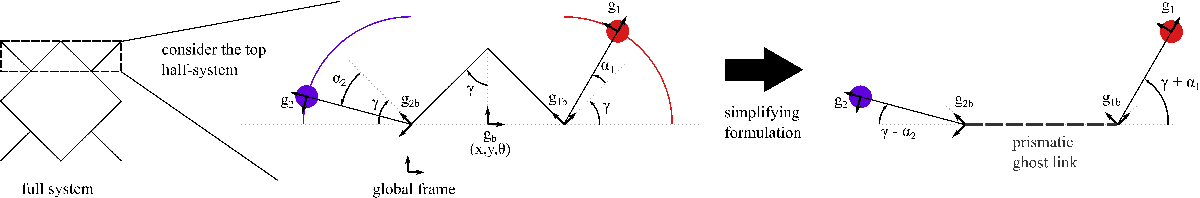

We approach this problem as follows,

1) First we fix the left leg as the base frame and constrain the right-leg translational velocities to zero. Note that the middle link is prismatic with positive expansion rate $\dot{\;l\;}$, and correspondingly have the end frames on the left and right (consider the figure on the right) move apart from each other at $-\frac{\dot{\;l} }{2}$ and $\frac{\dot{\;l} }{2}$ respectively. 

2) Then we find that map that takes the two leg angle shapes and middle link prismatic shape to the body velocity.

Finally, as Capprin recommended, we can look at the lie-bracket over the two leg-angles to compute if there is a net change in length of the center link. In some cases, we many cases we might need the center link to change length!

% define your variables
syms alpha_1 alpha_2 alpha_dot_1 alpha_dot_2 l gamma gamma_dot g_dot_1__theta real

% define vector that help choosing columns in our jacobians
x_dot = [1,0,0]'; y_dot = [0,1,0]'; theta_dot = [0,0,1]';

% Let's define the phantom prismatic link length
mid = 2*l*sin(gamma);

% Inline function to define the SE2 vector:
v_SE2 = @(arm,arm_angle,rota) [arm*cos(arm_angle), arm*sin(arm_angle), rota]';

% ~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~
% define the transforms for various joints (all transforms needed):
% ~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~
H_2__2b = simplify(v2M_SE2(v_SE2(-l, 0, -alpha_2)))

$$H\_2\_\_2b = \left(\begin{array}{ccc} \cos\left(\alpha_{2}\right) & \sin\left(\alpha_{2}\right) & -l\\ -\sin\left(\alpha_{2}\right) & \cos\left(\alpha_{2}\right) & 0\\ 0 & 0 & 1 \end{array}\right)$$

H_2b__2 = simplify(v2M_SE2(v_SE2(l, alpha_2, alpha_2)))

$$H\_2b\_\_2 = \left(\begin{array}{ccc} \cos\left(\alpha_{2}\right) & -\sin\left(\alpha_{2}\right) & l\,\cos\left(\alpha_{2}\right)\\ \sin\left(\alpha_{2}\right) & \cos\left(\alpha_{2}\right) & l\,\sin\left(\alpha_{2}\right)\\ 0 & 0 & 1 \end{array}\right)$$

H_2b__b = simplify(v2M_SE2(v_SE2(0.5*mid, gamma - pi, gamma - pi)))

$$H\_2b\_\_b = \left(\begin{array}{ccc} -\cos\left(\gamma \right) & \sin\left(\gamma \right) & -\frac{l\,\sin\left(2\,\gamma \right)}{2}\\ -\sin\left(\gamma \right) & -\cos\left(\gamma \right) & -l\,{\sin\left(\gamma \right)}^{2}\\ 0 & 0 & 1 \end{array}\right)$$

H_b__2b = simplify(v2M_SE2(v_SE2(-0.5*mid, 0, pi - gamma)))

$$H\_b\_\_2b = \left(\begin{array}{ccc} -\cos\left(\gamma \right) & -\sin\left(\gamma \right) & -l\,\sin\left(\gamma \right)\\ \sin\left(\gamma \right) & -\cos\left(\gamma \right) & 0\\ 0 & 0 & 1 \end{array}\right)$$

H_b__1b = simplify(v2M_SE2(v_SE2(0.5*mid, 0, gamma)))

$$H\_b\_\_1b = \left(\begin{array}{ccc} \cos\left(\gamma \right) & -\sin\left(\gamma \right) & l\,\sin\left(\gamma \right)\\ \sin\left(\gamma \right) & \cos\left(\gamma \right) & 0\\ 0 & 0 & 1 \end{array}\right)$$

H_1b__b = simplify(v2M_SE2(v_SE2(0.5*mid, pi - gamma, -gamma)))

$$H\_1b\_\_b = \left(\begin{array}{ccc} \cos\left(\gamma \right) & \sin\left(\gamma \right) & -\frac{l\,\sin\left(2\,\gamma \right)}{2}\\ -\sin\left(\gamma \right) & \cos\left(\gamma \right) & l\,{\sin\left(\gamma \right)}^{2}\\ 0 & 0 & 1 \end{array}\right)$$

H_1b__1 = simplify(v2M_SE2(v_SE2(l, alpha_1, alpha_1)))

$$H\_1b\_\_1 = \left(\begin{array}{ccc} \cos\left(\alpha_{1}\right) & -\sin\left(\alpha_{1}\right) & l\,\cos\left(\alpha_{1}\right)\\ \sin\left(\alpha_{1}\right) & \cos\left(\alpha_{1}\right) & l\,\sin\left(\alpha_{1}\right)\\ 0 & 0 & 1 \end{array}\right)$$

H_1__1b = simplify(v2M_SE2(v_SE2(-l, 0, -alpha_1)))

$$H\_1\_\_1b = \left(\begin{array}{ccc} \cos\left(\alpha_{1}\right) & \sin\left(\alpha_{1}\right) & -l\\ -\sin\left(\alpha_{1}\right) & \cos\left(\alpha_{1}\right) & 0\\ 0 & 0 & 1 \end{array}\right)$$

% Now, we do the first process -- get the translational velocities of g_1
% in terms of g_2's rotational velocity and limb velocities
H_2__1 = simplify(H_2__2b*H_2b__b*H_b__1b*H_1b__1,'Steps',10)

$$H\_2\_\_1 = \begin{array}{l} \left(\begin{array}{ccc} -\cos\left(\alpha_{1}-\alpha_{2}+2\,\gamma \right) & \sigma_{1} & -l\,\left(\cos\left(\alpha_{1}-\alpha_{2}+2\,\gamma \right)+\sin\left(\alpha_{2}\right)-\sin\left(\alpha_{2}-2\,\gamma \right)+1\right)\\ -\sigma_{1} & -\cos\left(\alpha_{1}-\alpha_{2}+2\,\gamma \right) & -l\,\left(\sigma_{1}+\cos\left(\alpha_{2}\right)-\cos\left(\alpha_{2}-2\,\gamma \right)\right)\\ 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sin\left(\alpha_{1}-\alpha_{2}+2\,\gamma \right) \end{array}$$

h_2__1 = M2v_SE2(H_2__1)

$$h\_2\_\_1 = \left(\begin{array}{c} -l\,\left(\cos\left(\alpha_{1}-\alpha_{2}+2\,\gamma \right)+\sin\left(\alpha_{2}\right)-\sin\left(\alpha_{2}-2\,\gamma \right)+1\right)\\ -l\,\left(\sin\left(\alpha_{1}-\alpha_{2}+2\,\gamma \right)+\cos\left(\alpha_{2}\right)-\cos\left(\alpha_{2}-2\,\gamma \right)\right)\\ \alpha_{1}-\alpha_{2}+2\,\gamma \end{array}\right)$$

% Now, we get the end frames on the phantom prismatic link g1b and g2b's
% transform to the end effector g1
H_2b__1 = simplify(H_2b__b*H_b__1b*H_1b__1,'Steps',10)

$$H\_2b\_\_1 = \left(\begin{array}{ccc} -\cos\left(\alpha_{1}+2\,\gamma \right) & \sin\left(\alpha_{1}+2\,\gamma \right) & -l\,\left(\sin\left(2\,\gamma \right)+\cos\left(\alpha_{1}+2\,\gamma \right)\right)\\ -\sin\left(\alpha_{1}+2\,\gamma \right) & -\cos\left(\alpha_{1}+2\,\gamma \right) & -l\,\left(2\,{\sin\left(\gamma \right)}^{2}+\sin\left(\alpha_{1}+2\,\gamma \right)\right)\\ 0 & 0 & 1 \end{array}\right)$$

h_2b__1 = M2v_SE2(H_2b__1)

$$h\_2b\_\_1 = \left(\begin{array}{c} -l\,\left(\sin\left(2\,\gamma \right)+\cos\left(\alpha_{1}+2\,\gamma \right)\right)\\ -l\,\left(2\,{\sin\left(\gamma \right)}^{2}+\sin\left(\alpha_{1}+2\,\gamma \right)\right)\\ \alpha_{1}+2\,\gamma \end{array}\right)$$

h_1b__1 = M2v_SE2(H_1b__1)

$$h\_1b\_\_1 = \left(\begin{array}{c} l\,\cos\left(\alpha_{1}\right)\\ l\,\sin\left(\alpha_{1}\right)\\ \alpha_{1} \end{array}\right)$$

% Now, we find the jacobians that will transfer velocities to the end
% effector -- for all of these terms we only need the rotational velocities
J_2__1 = AdjInvMap(h_2__1)

$$J\_2\_\_1 = \begin{array}{l} \left(\begin{array}{ccc} \sigma_{2} & \sigma_{1} & -l\,\left(\sigma_{1}+\cos\left(\alpha_{1}\right)-\cos\left(\alpha_{1}+2\,\gamma \right)\right)\\ -\sigma_{1} & \sigma_{2} & -l\,\left(\sigma_{2}-\sin\left(\alpha_{1}\right)+\sin\left(\alpha_{1}+2\,\gamma \right)+1\right)\\ 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sin\left(\alpha_{1}-\alpha_{2}+2\,\gamma \right)\\ \sigma_{2}=\cos\left(\alpha_{1}-\alpha_{2}+2\,\gamma \right) \end{array}$$

J_2b__1 = AdjInvMap(h_2b__1)

$$J\_2b\_\_1 = \left(\begin{array}{ccc} \cos\left(\alpha_{1}+2\,\gamma \right) & \sin\left(\alpha_{1}+2\,\gamma \right) & -l\,\left(\cos\left(\alpha_{1}\right)-\cos\left(\alpha_{1}+2\,\gamma \right)\right)\\ -\sin\left(\alpha_{1}+2\,\gamma \right) & \cos\left(\alpha_{1}+2\,\gamma \right) & -l\,\left(\sin\left(\alpha_{1}+2\,\gamma \right)-\sin\left(\alpha_{1}\right)+1\right)\\ 0 & 0 & 1 \end{array}\right)$$

J_1b__1 = AdjInvMap(h_1b__1)

$$J\_1b\_\_1 = \left(\begin{array}{ccc} \cos\left(\alpha_{1}\right) & \sin\left(\alpha_{1}\right) & 0\\ -\sin\left(\alpha_{1}\right) & \cos\left(\alpha_{1}\right) & l\\ 0 & 0 & 1 \end{array}\right)$$

% Now, we define the velocities generated at each point:
% 1) rotational velocity at the first frame that's fixed
J_2rot = J_2__1*theta_dot

$$J\_2rot = \left(\begin{array}{c} -l\,\left(\sin\left(\alpha_{1}-\alpha_{2}+2\,\gamma \right)+\cos\left(\alpha_{1}\right)-\cos\left(\alpha_{1}+2\,\gamma \right)\right)\\ -l\,\left(\cos\left(\alpha_{1}-\alpha_{2}+2\,\gamma \right)-\sin\left(\alpha_{1}\right)+\sin\left(\alpha_{1}+2\,\gamma \right)+1\right)\\ 1 \end{array}\right)$$

% 2) gamma_dot velocity at g_1b and g_2b frames
J_prismatic = J_2b__1*[l, 0, -1]' + J_1b__1*[l, 0, 1]'

$$J\_prismatic = \left(\begin{array}{c} l\,\left(\cos\left(\alpha_{1}\right)-\cos\left(\alpha_{1}+2\,\gamma \right)\right)+l\,\cos\left(\alpha_{1}\right)+l\,\cos\left(\alpha_{1}+2\,\gamma \right)\\ l+l\,\left(\sin\left(\alpha_{1}+2\,\gamma \right)-\sin\left(\alpha_{1}\right)+1\right)-l\,\sin\left(\alpha_{1}\right)-l\,\sin\left(\alpha_{1}+2\,\gamma \right)\\ 0 \end{array}\right)$$

% 3) limb rotation velocities
J_alpha_1 = J_1b__1*theta_dot

$$J\_alpha\_1 = \left(\begin{array}{c} 0\\ l\\ 1 \end{array}\right)$$

J_alpha_2 = J_2b__1*theta_dot

$$J\_alpha\_2 = \left(\begin{array}{c} -l\,\left(\cos\left(\alpha_{1}\right)-\cos\left(\alpha_{1}+2\,\gamma \right)\right)\\ -l\,\left(\sin\left(\alpha_{1}+2\,\gamma \right)-\sin\left(\alpha_{1}\right)+1\right)\\ 1 \end{array}\right)$$

% Now, we assemble the full jacobian and equate it to zero as shown below


$$\left\lbrack \begin{array}{c}
0\\
0
\end{array}\right\rbrack =\left\lbrack \begin{array}{ccc}
1 & 0 & 0\\
0 & 1 & 0
\end{array}\right\rbrack \left\lbrack \begin{array}{cccc}
J_{\frac{1}{2}}^{\theta \;}  & J_p  & J_{\alpha_1 }  & J_{\alpha_2 } 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
{\dot{g} }_2^{\theta } \\
\dot{\gamma \;} \\
{\dot{\alpha} }_1 \\
{\dot{\alpha} }_2 
\end{array}\right\rbrack \Rightarrow \left\lbrack \begin{array}{c}
{\dot{g} }_2^{\theta } \\
\dot{\gamma \;} 
\end{array}\right\rbrack =-{\left\lbrack \begin{array}{cc}
J_{\frac{1}{2}}^{\theta \;}  & J_p 
\end{array}\right\rbrack }^{-1} \left\lbrack \begin{array}{cc}
J_{\alpha_1 }  & J_{\alpha_2 } 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
{\dot{\alpha} }_1 \\
{\dot{\alpha} }_2 
\end{array}\right\rbrack$$


% Now, lets get this full transform to foot rotational velocities and body
% shape change rate from the limb rotation rates.
omega = simplify([eye(2),zeros(2,1)]*[J_2rot, J_prismatic,J_alpha_1, J_alpha_2],'Steps',10)

$$omega = \begin{array}{l} \left(\begin{array}{cccc} -l\,\left(\sin\left(\alpha_{1}-\alpha_{2}+2\,\gamma \right)+\cos\left(\alpha_{1}\right)-\sigma_{2}\right) & 2\,l\,\cos\left(\alpha_{1}\right) & 0 & -l\,\left(\cos\left(\alpha_{1}\right)-\sigma_{2}\right)\\ -l\,\left(\cos\left(\alpha_{1}-\alpha_{2}+2\,\gamma \right)-\sin\left(\alpha_{1}\right)+\sigma_{1}+1\right) & -2\,l\,\left(\sin\left(\alpha_{1}\right)-1\right) & l & -l\,\left(\sigma_{1}-\sin\left(\alpha_{1}\right)+1\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sin\left(\alpha_{1}+2\,\gamma \right)\\ \sigma_{2}=\cos\left(\alpha_{1}+2\,\gamma \right) \end{array}$$

omega_1p = simplify(-omega(:,1:2)^-1 * omega(:,3:4),'Steps',10)

$$omega\_1p = \begin{array}{l} \left(\begin{array}{cc} \frac{\cos\left(\alpha_{1}\right)}{\sigma_{1}} & -\frac{\sin\left(2\,\gamma \right)+\cos\left(\alpha_{1}+2\,\gamma \right)}{\sigma_{1}}\\ \frac{\sin\left(\alpha_{1}-\alpha_{2}+2\,\gamma \right)+\cos\left(\alpha_{1}\right)-\cos\left(\alpha_{1}+2\,\gamma \right)}{2\,\sigma_{1}} & -\frac{\sin\left(\alpha_{1}-\alpha_{2}+2\,\gamma \right)+\cos\left(\alpha_{2}\right)-\cos\left(\alpha_{2}-2\,\gamma \right)}{2\,\sigma_{1}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sin\left(2\,\gamma \right)-\sin\left(\alpha_{1}-\alpha_{2}+2\,\gamma \right)+\cos\left(\alpha_{1}+2\,\gamma \right)+\cos\left(\alpha_{2}-2\,\gamma \right) \end{array}$$

Let's see what this matrix looks like at the system's mean position,

omega_1p_mean = subs(omega_1p, [alpha_1, alpha_2, gamma], [0, 0, pi/2])

$$omega\_1p\_mean = \left(\begin{array}{cc} -\frac{1}{2} & -\frac{1}{2}\\ -\frac{1}{2} & \frac{1}{2} \end{array}\right)$$

Doesn't look singular at the mean position -- let's complete the formulation to get a sense for what this looks like.

% Find the contribution of 2b and 1b on the body
h_2b__b = M2v_SE2(H_2b__b)

$$h\_2b\_\_b = \left(\begin{array}{c} -\frac{l\,\sin\left(2\,\gamma \right)}{2}\\ -l\,{\sin\left(\gamma \right)}^{2}\\ \gamma \end{array}\right)$$

h_1b__b = M2v_SE2(H_1b__b)

$$h\_1b\_\_b = \left(\begin{array}{c} -\frac{l\,\sin\left(2\,\gamma \right)}{2}\\ l\,{\sin\left(\gamma \right)}^{2}\\ -\gamma \end{array}\right)$$

J_2b__b = AdjInvMap(h_2b__b)

$$J\_2b\_\_b = \left(\begin{array}{ccc} \cos\left(\gamma \right) & \sin\left(\gamma \right) & 0\\ -\sin\left(\gamma \right) & \cos\left(\gamma \right) & -l\,\sin\left(\gamma \right)\\ 0 & 0 & 1 \end{array}\right)$$

J_1b__b = AdjInvMap(h_1b__b)

$$J\_1b\_\_b = \left(\begin{array}{ccc} \cos\left(\gamma \right) & -\sin\left(\gamma \right) & 0\\ \sin\left(\gamma \right) & \cos\left(\gamma \right) & -l\,\sin\left(\gamma \right)\\ 0 & 0 & 1 \end{array}\right)$$

J_g__b = J_2b__b*[l, 0, -1]' + J_1b__b*[l, 0, 1]'

$$J\_g\_\_b = \left(\begin{array}{c} 2\,l\,\cos\left(\gamma \right)\\ 0\\ 0 \end{array}\right)$$

J_alpha2__b = J_2b__b*theta_dot

$$J\_alpha2\_\_b = \left(\begin{array}{c} 0\\ -l\,\sin\left(\gamma \right)\\ 1 \end{array}\right)$$

J_alpha1__b = J_1b__b*theta_dot

$$J\_alpha1\_\_b = \left(\begin{array}{c} 0\\ -l\,\sin\left(\gamma \right)\\ 1 \end{array}\right)$$

The final jacobian from limb velocities to body velocity is given by,

J_full = simplify([J_alpha1__b, J_alpha2__b, J_g__b]*[1,0,0,0;
                                            0,1,0,0;
                                            0,0,0,1]*[eye(2);omega_1p],'Steps',10)

$$J\_full = \begin{array}{l} \left(\begin{array}{cc} \frac{l\,\cos\left(\gamma \right)\,\left(\sin\left(\alpha_{1}-\alpha_{2}+2\,\gamma \right)+\cos\left(\alpha_{1}\right)-\cos\left(\alpha_{1}+2\,\gamma \right)\right)}{\sigma_{1}} & -\frac{l\,\cos\left(\gamma \right)\,\left(\sin\left(\alpha_{1}-\alpha_{2}+2\,\gamma \right)+\cos\left(\alpha_{2}\right)-\cos\left(\alpha_{2}-2\,\gamma \right)\right)}{\sigma_{1}}\\ -l\,\sin\left(\gamma \right) & -l\,\sin\left(\gamma \right)\\ 1 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sin\left(2\,\gamma \right)-\sin\left(\alpha_{1}-\alpha_{2}+2\,\gamma \right)+\cos\left(\alpha_{1}+2\,\gamma \right)+\cos\left(\alpha_{2}-2\,\gamma \right) \end{array}$$

Let's evaluate this jacobian at mean robot position

J_full_mean = subs(J_full,[alpha_1,alpha_2,gamma],[0, 0, pi/2])

$$J\_full\_mean = \left(\begin{array}{cc} 0 & 0\\ -l & -l\\ 1 & 1 \end{array}\right)$$

This is an invalid position since if I try a 'breast-stroke'-kinda gait with ${\dot{\alpha} }_1 ={\dot{-\alpha } }_2 =-k,\;\;k\in Z^+$, we get no motion since it is a bifurcation point.

**Metric: **Let's use the same rate-limit of 1 rad/s for both legs -- hence an identity metric.

Also, let's assume for the $\gamma$-controlled case (or all shapes are controlled), the **A** matrix is given by,

A_fullC = simplify([J_alpha1__b, J_alpha2__b,J_g__b],'Steps',10)

$$A\_fullC = \left(\begin{array}{ccc} 0 & 0 & 2\,l\,\cos\left(\gamma \right)\\ -l\,\sin\left(\gamma \right) & -l\,\sin\left(\gamma \right) & 0\\ 1 & 1 & 0 \end{array}\right)$$

## Important Takeaways

Where you start the gait is important -- below you find a plots the inter-leg distance as a function of $\alpha_1$, $\alpha_2$, and $\gamma$.

 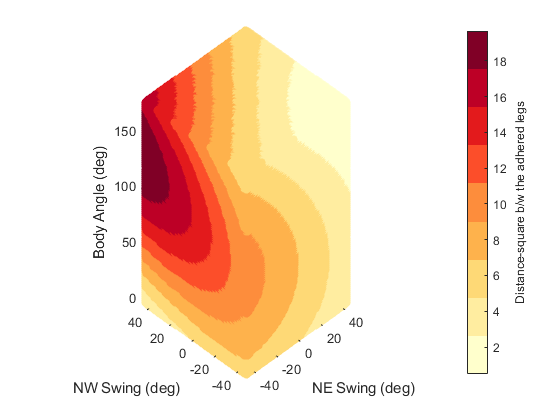

NE and NW swing refer to $\alpha_1$ and $\alpha_2$ respectively!

## Kinematic Solver and Geometric Local Connection based on inter-leg constraints

We start by writing transforms to each leg tip,

syms x y theta alpha_1 alpha_2 gamma l a real
vec_SE2 = @(x_arm,y_arm,rota) [x_arm, y_arm, rota]';
h_e__0 = vec_SE2(x, y, theta)

$$h\_e\_\_0 = \left(\begin{array}{c} x\\ y\\ \theta \end{array}\right)$$

H_e__0 = v2M_SE2(h_e__0)

$$H\_e\_\_0 = \left(\begin{array}{ccc} \cos\left(\theta \right) & -\sin\left(\theta \right) & x\\ \sin\left(\theta \right) & \cos\left(\theta \right) & y\\ 0 & 0 & 1 \end{array}\right)$$

% define the leg position for the top two legs (base and leg tip)
h_0__1b = v_SE2(l, gamma, gamma);
H_0__1b = v2M_SE2(h_0__1b)

$$H\_0\_\_1b = \left(\begin{array}{ccc} \cos\left(\gamma \right) & -\sin\left(\gamma \right) & l\,\cos\left(\gamma \right)\\ \sin\left(\gamma \right) & \cos\left(\gamma \right) & l\,\sin\left(\gamma \right)\\ 0 & 0 & 1 \end{array}\right)$$

h_1b__1 = v_SE2(a*l, alpha_1, alpha_1);
H_1b__1 = v2M_SE2(h_1b__1)

$$H\_1b\_\_1 = \left(\begin{array}{ccc} \cos\left(\alpha_{1}\right) & -\sin\left(\alpha_{1}\right) & a\,l\,\cos\left(\alpha_{1}\right)\\ \sin\left(\alpha_{1}\right) & \cos\left(\alpha_{1}\right) & a\,l\,\sin\left(\alpha_{1}\right)\\ 0 & 0 & 1 \end{array}\right)$$

H_e__1 = simplify(H_e__0*H_0__1b*H_1b__1,'Steps',10)

$$H\_e\_\_1 = \left(\begin{array}{ccc} \cos\left(\alpha_{1}+\gamma +\theta \right) & -\sin\left(\alpha_{1}+\gamma +\theta \right) & x+l\,\cos\left(\gamma +\theta \right)+a\,l\,\cos\left(\alpha_{1}+\gamma +\theta \right)\\ \sin\left(\alpha_{1}+\gamma +\theta \right) & \cos\left(\alpha_{1}+\gamma +\theta \right) & y+l\,\sin\left(\gamma +\theta \right)+a\,l\,\sin\left(\alpha_{1}+\gamma +\theta \right)\\ 0 & 0 & 1 \end{array}\right)$$

h_0__2b = v_SE2(l, pi-gamma, pi-gamma);
H_0__2b = v2M_SE2(h_0__2b)

$$H\_0\_\_2b = \left(\begin{array}{ccc} -\cos\left(\gamma \right) & -\sin\left(\gamma \right) & -l\,\cos\left(\gamma \right)\\ \sin\left(\gamma \right) & -\cos\left(\gamma \right) & l\,\sin\left(\gamma \right)\\ 0 & 0 & 1 \end{array}\right)$$

h_2b__2 = v_SE2(a*l, alpha_2, alpha_2);
H_2b__2 = v2M_SE2(h_2b__2)

$$H\_2b\_\_2 = \left(\begin{array}{ccc} \cos\left(\alpha_{2}\right) & -\sin\left(\alpha_{2}\right) & a\,l\,\cos\left(\alpha_{2}\right)\\ \sin\left(\alpha_{2}\right) & \cos\left(\alpha_{2}\right) & a\,l\,\sin\left(\alpha_{2}\right)\\ 0 & 0 & 1 \end{array}\right)$$

H_e__2 = simplify(H_e__0*H_0__2b*H_2b__2,'Steps',10)

$$H\_e\_\_2 = \left(\begin{array}{ccc} -\cos\left(\alpha_{2}-\gamma +\theta \right) & \sin\left(\alpha_{2}-\gamma +\theta \right) & x-l\,\cos\left(\gamma -\theta \right)-a\,l\,\cos\left(\alpha_{2}-\gamma +\theta \right)\\ -\sin\left(\alpha_{2}-\gamma +\theta \right) & -\cos\left(\alpha_{2}-\gamma +\theta \right) & y+l\,\sin\left(\gamma -\theta \right)-a\,l\,\sin\left(\alpha_{2}-\gamma +\theta \right)\\ 0 & 0 & 1 \end{array}\right)$$

Notice that this is a nonlinear function of $\theta \;$as well and hence breaks the standard symmetry in Geometric Mechanics. Let's explore this a little further,

h_e__1 = M2v_SE2(H_e__1); h_e__2 = M2v_SE2(H_e__2);
% Consider only the first two elements of the three element SE(2) vector:
choose_12 = [eye(2), zeros(2,1);
            zeros(1,3)];
% Get the distance vector:
kvec = choose_12*(h_e__1-h_e__2)

$$kvec = \left(\begin{array}{c} l\,\cos\left(\gamma +\theta \right)+l\,\cos\left(\gamma -\theta \right)+a\,l\,\cos\left(\alpha_{1}+\gamma +\theta \right)+a\,l\,\cos\left(\alpha_{2}-\gamma +\theta \right)\\ l\,\sin\left(\gamma +\theta \right)-l\,\sin\left(\gamma -\theta \right)+a\,l\,\sin\left(\alpha_{1}+\gamma +\theta \right)+a\,l\,\sin\left(\alpha_{2}-\gamma +\theta \right)\\ 0 \end{array}\right)$$

**Taking analytical derivatives, and simplifying we have the following two expressions (ignoring the third row),**

$e_{31} \;\dot{\gamma} +e_{31a} \;{\dot{\;\alpha } }_1 +e_{32a} \;{\dot{\;\alpha } }_2 =e_{32} \;\dot{\theta}$**, **

$e_{41} \;\dot{\gamma} +e_{41a} \;{\dot{\;\alpha } }_1 +e_{42a} \;{\dot{\;\alpha } }_2 =e_{42} \;\dot{\theta}$.

expr32 = sin(gamma+theta) - sin(gamma-theta) + a*sin(alpha_1+gamma+theta) + a*sin(alpha_2-gamma+theta)

$$expr32 = \sin\left(\gamma +\theta \right)-\sin\left(\gamma -\theta \right)+a\,\sin\left(\alpha_{2}-\gamma +\theta \right)+a\,\sin\left(\alpha_{1}+\gamma +\theta \right)$$

expr31 = -sin(gamma+theta) - sin(gamma-theta) - a*sin(alpha_1+gamma+theta) + a*sin(alpha_2-gamma+theta)

$$expr31 = a\,\sin\left(\alpha_{2}-\gamma +\theta \right)-\sin\left(\gamma +\theta \right)-\sin\left(\gamma -\theta \right)-a\,\sin\left(\alpha_{1}+\gamma +\theta \right)$$

expr31a =  -a*sin(alpha_1+gamma+theta); expr32a = -a*sin(alpha_2-gamma+theta); % no simplification needed
expr41 = cos(gamma+theta) - cos(gamma-theta) + a*cos(alpha_1+gamma+theta) - a*cos(alpha_2-gamma+theta)

$$expr41 = \cos\left(\gamma +\theta \right)-\cos\left(\gamma -\theta \right)-a\,\cos\left(\alpha_{2}-\gamma +\theta \right)+a\,\cos\left(\alpha_{1}+\gamma +\theta \right)$$

expr42 = -cos(gamma+theta) - cos(gamma-theta) - a*cos(alpha_1+gamma+theta) - a*cos(alpha_2-gamma+theta)

$$expr42 = -\cos\left(\gamma +\theta \right)-\cos\left(\gamma -\theta \right)-a\,\cos\left(\alpha_{2}-\gamma +\theta \right)-a\,\cos\left(\alpha_{1}+\gamma +\theta \right)$$

expr41a =  a*cos(alpha_1+gamma+theta); expr42a = a*cos(alpha_2-gamma+theta); % no simplification needed

Now, we can work out the simplifications.

gamma_hat = simplify(expr31/expr32 - expr41/expr42, 'Steps', 50)

$$gamma\_hat = -\frac{2\,\left(\sin\left(2\,\gamma \right)+a\,\sin\left(\alpha_{1}+2\,\gamma \right)-a\,\sin\left(\alpha_{2}-2\,\gamma \right)+a^{2}\,\sin\left(\alpha_{1}-\alpha_{2}+2\,\gamma \right)\right)}{\left(\sin\left(\gamma +\theta \right)-\sin\left(\gamma -\theta \right)+a\,\sin\left(\alpha_{2}-\gamma +\theta \right)+a\,\sin\left(\alpha_{1}+\gamma +\theta \right)\right)\,\left(\cos\left(\gamma +\theta \right)+\cos\left(\gamma -\theta \right)+a\,\cos\left(\alpha_{2}-\gamma +\theta \right)+a\,\cos\left(\alpha_{1}+\gamma +\theta \right)\right)}$$

alpha_hat_1 = expr41a/expr42 - expr31a/expr32 % we don't have to simplify this expression and the one below

$$alpha\_hat\_1 = \frac{a\,\sin\left(\alpha_{1}+\gamma +\theta \right)}{\sin\left(\gamma +\theta \right)-\sin\left(\gamma -\theta \right)+a\,\sin\left(\alpha_{2}-\gamma +\theta \right)+a\,\sin\left(\alpha_{1}+\gamma +\theta \right)}-\frac{a\,\cos\left(\alpha_{1}+\gamma +\theta \right)}{\cos\left(\gamma +\theta \right)+\cos\left(\gamma -\theta \right)+a\,\cos\left(\alpha_{2}-\gamma +\theta \right)+a\,\cos\left(\alpha_{1}+\gamma +\theta \right)}$$

alpha_hat_2 = expr42a/expr42 - expr32a/expr32

$$alpha\_hat\_2 = \frac{a\,\sin\left(\alpha_{2}-\gamma +\theta \right)}{\sin\left(\gamma +\theta \right)-\sin\left(\gamma -\theta \right)+a\,\sin\left(\alpha_{2}-\gamma +\theta \right)+a\,\sin\left(\alpha_{1}+\gamma +\theta \right)}-\frac{a\,\cos\left(\alpha_{2}-\gamma +\theta \right)}{\cos\left(\gamma +\theta \right)+\cos\left(\gamma -\theta \right)+a\,\cos\left(\alpha_{2}-\gamma +\theta \right)+a\,\cos\left(\alpha_{1}+\gamma +\theta \right)}$$

Compute the final coefficients of the map from the leg-swing velocities ($\dot{\alpha}$) to sprawl velocity ($\dot{\gamma}$),

alpha_coeff_1_gamma = simplify((gamma_hat^-1)*alpha_hat_1, 'Steps', 50)

$$alpha\_coeff\_1\_gamma = -\frac{a\,\left(\sin\left(\alpha_{1}\right)+\sin\left(\alpha_{1}+2\,\gamma \right)+a\,\sin\left(\alpha_{1}-\alpha_{2}+2\,\gamma \right)\right)}{2\,\left(\sin\left(2\,\gamma \right)+a\,\sin\left(\alpha_{1}+2\,\gamma \right)-a\,\sin\left(\alpha_{2}-2\,\gamma \right)+a^{2}\,\sin\left(\alpha_{1}-\alpha_{2}+2\,\gamma \right)\right)}$$

alpha_coeff_2_gamma = simplify((gamma_hat^-1)*alpha_hat_2, 'Steps', 50)

$$alpha\_coeff\_2\_gamma = -\frac{a\,\left(\sin\left(\alpha_{2}\right)+\sin\left(\alpha_{2}-2\,\gamma \right)-a\,\sin\left(\alpha_{1}-\alpha_{2}+2\,\gamma \right)\right)}{2\,\left(\sin\left(2\,\gamma \right)+a\,\sin\left(\alpha_{1}+2\,\gamma \right)-a\,\sin\left(\alpha_{2}-2\,\gamma \right)+a^{2}\,\sin\left(\alpha_{1}-\alpha_{2}+2\,\gamma \right)\right)}$$

% gamma_map
gamma_map = [alpha_coeff_1_gamma alpha_coeff_2_gamma]

$$gamma\_map = \begin{array}{l} \left(\begin{array}{cc} -\frac{a\,\left(\sin\left(\alpha_{1}\right)+\sin\left(\alpha_{1}+2\,\gamma \right)+a\,\sin\left(\alpha_{1}-\alpha_{2}+2\,\gamma \right)\right)}{\sigma_{1}} & -\frac{a\,\left(\sin\left(\alpha_{2}\right)+\sin\left(\alpha_{2}-2\,\gamma \right)-a\,\sin\left(\alpha_{1}-\alpha_{2}+2\,\gamma \right)\right)}{\sigma_{1}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=2\,\left(\sin\left(2\,\gamma \right)+a\,\sin\left(\alpha_{1}+2\,\gamma \right)-a\,\sin\left(\alpha_{2}-2\,\gamma \right)+a^{2}\,\sin\left(\alpha_{1}-\alpha_{2}+2\,\gamma \right)\right) \end{array}$$

As a next step, we now compute the system's rotational velocity ($\dot{\theta}$) as a function of the leg-swing velocities ($\dot{\alpha}$),

$e_{32} \;\dot{\theta} -e_{31a} \;{\dot{\;\alpha } }_1 -e_{32a} \;{\dot{\;\alpha } }_2 =e_{31} \;\dot{\gamma}$**, **

$e_{42} \;\dot{\theta} -e_{41a} \;{\dot{\;\alpha } }_1 -e_{42a} \;{\dot{\;\alpha } }_2 =e_{41} \;\dot{\gamma}$.

Let's use the same approach as above to the obtain the coefficients,

theta_hat = simplify(expr32/expr31 - expr42/expr41, 'Steps', 50)

$$theta\_hat = \frac{2\,\left(\sin\left(2\,\gamma \right)+a\,\sin\left(\alpha_{1}+2\,\gamma \right)-a\,\sin\left(\alpha_{2}-2\,\gamma \right)+a^{2}\,\sin\left(\alpha_{1}-\alpha_{2}+2\,\gamma \right)\right)}{\left(\sin\left(\gamma -\theta \right)+\sin\left(\gamma +\theta \right)-a\,\sin\left(\alpha_{2}-\gamma +\theta \right)+a\,\sin\left(\alpha_{1}+\gamma +\theta \right)\right)\,\left(\cos\left(\gamma +\theta \right)-\cos\left(\gamma -\theta \right)-a\,\cos\left(\alpha_{2}-\gamma +\theta \right)+a\,\cos\left(\alpha_{1}+\gamma +\theta \right)\right)}$$

alpha_hat_1 = -expr41a/expr41 + expr31a/expr31

$$alpha\_hat\_1 = \frac{a\,\sin\left(\alpha_{1}+\gamma +\theta \right)}{\sin\left(\gamma -\theta \right)+\sin\left(\gamma +\theta \right)-a\,\sin\left(\alpha_{2}-\gamma +\theta \right)+a\,\sin\left(\alpha_{1}+\gamma +\theta \right)}-\frac{a\,\cos\left(\alpha_{1}+\gamma +\theta \right)}{\cos\left(\gamma +\theta \right)-\cos\left(\gamma -\theta \right)-a\,\cos\left(\alpha_{2}-\gamma +\theta \right)+a\,\cos\left(\alpha_{1}+\gamma +\theta \right)}$$

alpha_hat_2 = -expr42a/expr41 + expr32a/expr31

$$alpha\_hat\_2 = \frac{a\,\sin\left(\alpha_{2}-\gamma +\theta \right)}{\sin\left(\gamma -\theta \right)+\sin\left(\gamma +\theta \right)-a\,\sin\left(\alpha_{2}-\gamma +\theta \right)+a\,\sin\left(\alpha_{1}+\gamma +\theta \right)}-\frac{a\,\cos\left(\alpha_{2}-\gamma +\theta \right)}{\cos\left(\gamma +\theta \right)-\cos\left(\gamma -\theta \right)-a\,\cos\left(\alpha_{2}-\gamma +\theta \right)+a\,\cos\left(\alpha_{1}+\gamma +\theta \right)}$$

alpha_coeff_1_theta = simplify((theta_hat^-1)*alpha_hat_1, 'Steps', 50)

$$alpha\_coeff\_1\_theta = -\frac{a\,\left(\sin\left(\alpha_{1}+2\,\gamma \right)-\sin\left(\alpha_{1}\right)+a\,\sin\left(\alpha_{1}-\alpha_{2}+2\,\gamma \right)\right)}{2\,\left(\sin\left(2\,\gamma \right)+a\,\sin\left(\alpha_{1}+2\,\gamma \right)-a\,\sin\left(\alpha_{2}-2\,\gamma \right)+a^{2}\,\sin\left(\alpha_{1}-\alpha_{2}+2\,\gamma \right)\right)}$$

alpha_coeff_2_theta = simplify((theta_hat^-1)*alpha_hat_2, 'Steps', 50)

$$alpha\_coeff\_2\_theta = -\frac{a\,\left(\sin\left(\alpha_{2}\right)-\sin\left(\alpha_{2}-2\,\gamma \right)+a\,\sin\left(\alpha_{1}-\alpha_{2}+2\,\gamma \right)\right)}{2\,\left(\sin\left(2\,\gamma \right)+a\,\sin\left(\alpha_{1}+2\,\gamma \right)-a\,\sin\left(\alpha_{2}-2\,\gamma \right)+a^{2}\,\sin\left(\alpha_{1}-\alpha_{2}+2\,\gamma \right)\right)}$$

% theta_map
theta_map = [alpha_coeff_1_theta alpha_coeff_2_theta]

$$theta\_map = \begin{array}{l} \left(\begin{array}{cc} -\frac{a\,\left(\sin\left(\alpha_{1}+2\,\gamma \right)-\sin\left(\alpha_{1}\right)+a\,\sin\left(\alpha_{1}-\alpha_{2}+2\,\gamma \right)\right)}{\sigma_{1}} & -\frac{a\,\left(\sin\left(\alpha_{2}\right)-\sin\left(\alpha_{2}-2\,\gamma \right)+a\,\sin\left(\alpha_{1}-\alpha_{2}+2\,\gamma \right)\right)}{\sigma_{1}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=2\,\left(\sin\left(2\,\gamma \right)+a\,\sin\left(\alpha_{1}+2\,\gamma \right)-a\,\sin\left(\alpha_{2}-2\,\gamma \right)+a^{2}\,\sin\left(\alpha_{1}-\alpha_{2}+2\,\gamma \right)\right) \end{array}$$

Note that the denominator of the coefficients are the same for both sprawl and orientation maps, and this needs to be non-singular. Also, we can scale down the expression by a factor of two, and then plot the values as a heat map.

[~, cond_shape] = numden(alpha_coeff_1_theta)

$$cond\_shape = 2\,\sin\left(2\,\gamma \right)+2\,a\,\sin\left(\alpha_{1}+2\,\gamma \right)-2\,a\,\sin\left(\alpha_{2}-2\,\gamma \right)+2\,a^{2}\,\sin\left(\alpha_{1}-\alpha_{2}+2\,\gamma \right)$$

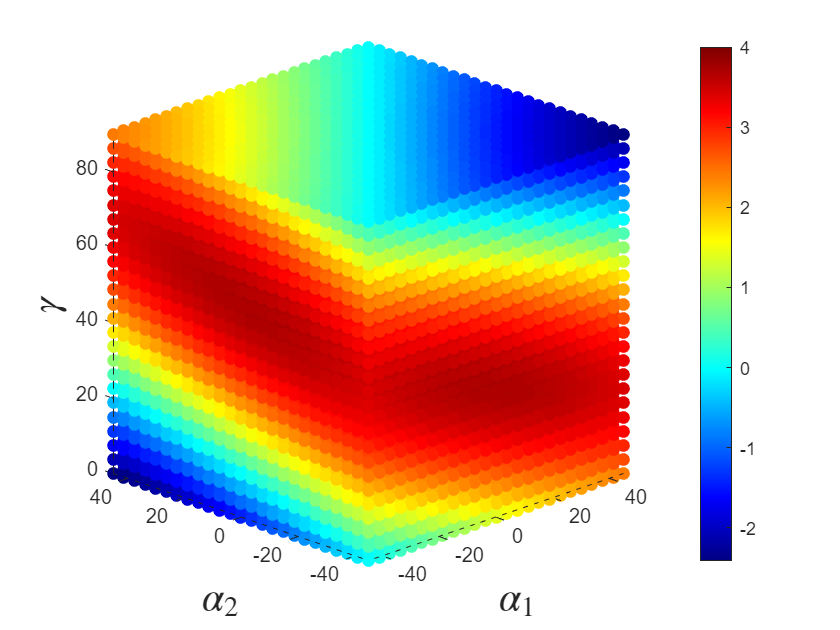

% Convert this into a function as well
cond_shape = cond_shape/2; cond_shape = matlabFunction(cond_shape);
% Number of points in each direction
num = 25;
% Initialize leg swing limits:
ank = pi/4;
% Initialize a domain for the shapes and mesh grid:
[A1,A2,G] = meshgrid(linspace(-ank,ank,num),linspace(-ank,ank,num),linspace(0,pi/2,num));
% Set the leg length fraction as 1:
A = 1; % try 'ones(size(A1))' if just '1' doesn't work
% Evaluate the function at these points:
c_shape = cond_shape(A,A1,A2,G);
% Make all the arrays linear:
a1 = reshape(A1,1,numel(A1)); a2 = reshape(A2,1,numel(A2)); g = reshape(G,1,numel(G));
c_shape = reshape(c_shape,1,numel(c_shape));
% Let's plot this:
figure()
scatter3(rad2deg(a1),rad2deg(a2),rad2deg(g),40,c_shape,'filled');
ax = gca;
view(-45,20)
xlabel('$\alpha_1$','Interpreter','latex','FontSize',20)
ylabel('$\alpha_2$','Interpreter','latex','FontSize',20)
zlabel('$\gamma$','Interpreter','latex','FontSize',20)
axis equal;
colormap(jet)
cb = colorbar;                        % create and label the colorbar

The singularity in our maps doesn't seem to be a function of the bifurcation, but rather indicates the inability to predict the change in sprawl or orientation of the system.

Here, we shall obtain the local connection for the augmented SE(2) locomotion of the system by incorporating the sprawl as the 4th position variable.

Analytical derivatives on the foot position (x and y components) are needed to obtain this map.

$\dot{x} =-\frac{1}{2}l\left\lbrack \begin{array}{cc}
\textrm{e31}\;{\hat{\alpha} }_1^{\theta \;} -\textrm{e32}\;{\hat{\alpha} }_1^{\gamma \;} +\textrm{e31a} & \textrm{e31}\;{\hat{\alpha} }_2^{\theta \;} -\textrm{e32}\;{\hat{\alpha} }_2^{\gamma \;} -\textrm{e32a}
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
{\dot{\alpha} }_1 \\
{\dot{\alpha} }_2 
\end{array}\right\rbrack$,

$\dot{y} =-\frac{1}{2}l\left\lbrack \begin{array}{cc}
\textrm{e41}\;{\hat{\alpha} }_1^{\theta \;} -\textrm{e42}\;{\hat{\alpha} }_1^{\gamma \;} +\textrm{e41a} & \textrm{e41}\;{\hat{\alpha} }_2^{\theta \;} -\textrm{e42}\;{\hat{\alpha} }_2^{\gamma \;} -\textrm{e42a}
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
{\dot{\alpha} }_1 \\
{\dot{\alpha} }_2 
\end{array}\right\rbrack$.

% x_map:
x_map = -0.5*l*[expr31*alpha_coeff_1_theta - expr32*alpha_coeff_1_gamma + expr31a, expr31*alpha_coeff_2_theta - expr32*alpha_coeff_2_gamma - expr32a];
x_map = simplify(x_map, 'Steps', 50)

$$x\_map = \begin{array}{l} \left(\begin{array}{cc} -\frac{a\,l\,\left(\cos\left(\alpha_{1}+\gamma -\theta \right)-\cos\left(\alpha_{1}-\gamma +\theta \right)-a\,\cos\left(\alpha_{1}+\alpha_{2}-\gamma +\theta \right)+a\,\cos\left(\alpha_{1}-\alpha_{2}+\gamma -\theta \right)\right)}{\sigma_{1}} & \frac{a\,l\,\left(\cos\left(\alpha_{2}+\gamma +\theta \right)-\cos\left(\gamma -\alpha_{2}+\theta \right)+a\,\cos\left(\alpha_{1}+\alpha_{2}+\gamma +\theta \right)-a\,\cos\left(\alpha_{1}-\alpha_{2}+\gamma +\theta \right)\right)}{\sigma_{1}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=2\,\left(\sin\left(2\,\gamma \right)+a\,\sin\left(\alpha_{1}+2\,\gamma \right)-a\,\sin\left(\alpha_{2}-2\,\gamma \right)+a^{2}\,\sin\left(\alpha_{1}-\alpha_{2}+2\,\gamma \right)\right) \end{array}$$

% y_map
y_map = -0.5*l*[expr41*alpha_coeff_1_theta - expr42*alpha_coeff_1_gamma + expr41a, expr41*alpha_coeff_2_theta - expr42*alpha_coeff_2_gamma - expr42a];
y_map = simplify(y_map, 'Steps', 50)

$$y\_map = \begin{array}{l} \left(\begin{array}{cc} \frac{a\,l\,\left(\sin\left(\alpha_{1}+\gamma -\theta \right)+\sin\left(\alpha_{1}-\gamma +\theta \right)+a\,\sin\left(\alpha_{1}+\alpha_{2}-\gamma +\theta \right)+a\,\sin\left(\alpha_{1}-\alpha_{2}+\gamma -\theta \right)\right)}{\sigma_{1}} & \frac{a\,l\,\left(\sin\left(\alpha_{2}+\gamma +\theta \right)-\sin\left(\gamma -\alpha_{2}+\theta \right)+a\,\sin\left(\alpha_{1}+\alpha_{2}+\gamma +\theta \right)-a\,\sin\left(\alpha_{1}-\alpha_{2}+\gamma +\theta \right)\right)}{\sigma_{1}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=2\,\left(\sin\left(2\,\gamma \right)+a\,\sin\left(\alpha_{1}+2\,\gamma \right)-a\,\sin\left(\alpha_{2}-2\,\gamma \right)+a^{2}\,\sin\left(\alpha_{1}-\alpha_{2}+2\,\gamma \right)\right) \end{array}$$

***The local connection is hence given by,***

local_conn = simplify([x_map;
                y_map;
                theta_map;
                gamma_map], "Steps", 50)

$$local\_conn = \begin{array}{l} \left(\begin{array}{cc} -\frac{a\,l\,\left(\cos\left(\alpha_{1}+\gamma -\theta \right)-\cos\left(\alpha_{1}-\gamma +\theta \right)-a\,\cos\left(\alpha_{1}+\alpha_{2}-\gamma +\theta \right)+a\,\cos\left(\alpha_{1}-\alpha_{2}+\gamma -\theta \right)\right)}{\sigma_{1}} & \frac{a\,l\,\left(\cos\left(\alpha_{2}+\gamma +\theta \right)-\cos\left(\gamma -\alpha_{2}+\theta \right)+a\,\cos\left(\alpha_{1}+\alpha_{2}+\gamma +\theta \right)-a\,\cos\left(\alpha_{1}-\alpha_{2}+\gamma +\theta \right)\right)}{\sigma_{1}}\\ \frac{a\,l\,\left(\sin\left(\alpha_{1}+\gamma -\theta \right)+\sin\left(\alpha_{1}-\gamma +\theta \right)+a\,\sin\left(\alpha_{1}+\alpha_{2}-\gamma +\theta \right)+a\,\sin\left(\alpha_{1}-\alpha_{2}+\gamma -\theta \right)\right)}{\sigma_{1}} & \frac{a\,l\,\left(\sin\left(\alpha_{2}+\gamma +\theta \right)-\sin\left(\gamma -\alpha_{2}+\theta \right)+a\,\sin\left(\alpha_{1}+\alpha_{2}+\gamma +\theta \right)-a\,\sin\left(\alpha_{1}-\alpha_{2}+\gamma +\theta \right)\right)}{\sigma_{1}}\\ -\frac{a\,\left(\sigma_{3}-\sin\left(\alpha_{1}\right)+a\,\sigma_{4}\right)}{\sigma_{1}} & -\frac{a\,\left(\sin\left(\alpha_{2}\right)-\sigma_{2}+a\,\sigma_{4}\right)}{\sigma_{1}}\\ -\frac{a\,\left(\sin\left(\alpha_{1}\right)+\sigma_{3}+a\,\sigma_{4}\right)}{\sigma_{1}} & -\frac{a\,\left(\sin\left(\alpha_{2}\right)+\sigma_{2}-a\,\sigma_{4}\right)}{\sigma_{1}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=2\,\left(\sin\left(2\,\gamma \right)+a\,\sigma_{3}-a\,\sigma_{2}+a^{2}\,\sigma_{4}\right)\\ \sigma_{2}=\sin\left(\alpha_{2}-2\,\gamma \right)\\ \sigma_{3}=\sin\left(\alpha_{1}+2\,\gamma \right)\\ \sigma_{4}=\sin\left(\alpha_{1}-\alpha_{2}+2\,\gamma \right) \end{array}$$

k0 = 1

kt = 0.7071 + 0.7071i

ans = 45